# **Synchronized BM Mode Acquisition Simulation - Version 4.0 - Ideal (No Saccades)**

**Author: Estéfano Machado Ferrer**

**Creation Date of Version 4.0 (DD/MM/YY): 13-06-2026**

**Last Modified Date (DD/MM/YY): 23-06-2026**

clc; clear; close all

Start timer:

tic

add codes path:

codes_path = fullfile(pwd, "Codes");   % open MATLAB in the repository root
addpath(genpath(codes_path));          % also adds Codes/k-Wave

## Experiment and file parameters for analysis and storage

Number of samples per horizontal scan (A-scans per B Scan) and number of total horizontal scans (number of B scans):

nBscans = 57;
nAscans = 57; % A-lines per B-Scan

Transition turn samples:

% Resolution of the transition turns:
nTurnSamples = 57;     % number of samples to discretize each transition turn

Type of experiment (Cylindrical or Non-Cylindrical)

prop_type_medium = 'Non_Cylindrical'

prop_type_medium = 'Non_Cylindrical'

Base path for results:

base_path = fullfile(fileparts(codes_path), "Results");
protocol_type = "SBM";
protocol_path = strcat(base_path,"/",protocol_type);

try
    cd(protocol_path);
catch
    mkdir(protocol_path);
    cd(protocol_path);
end

Build/load path for specific number of A-scans and B-scans in one BM Frame:

pattern_path = sprintf("%d_Ascans_%d_BScans_%d_TurnSamples", nAscans,nBscans,nTurnSamples);
try
    cd(pattern_path);
catch
    mkdir(pattern_path);
    cd(pattern_path);
end
run_path = pwd;

## Wave Propagation Simulation - Physical Phenomena

Recall that the Spherical Wave Equation, i.e. a restricted solution to the Helmholtz Equation is:

### 
$$\left( \mathbf{\nabla} ^2 - \frac{1}{c^2} \frac{\partial^2}{\partial t^2} \right) u(r,t) = 0$$


Then the *monochromatic* (harmonic, one frequency) solution to the wave equation is:

### 
$$u(r,t) = \frac{A}{r} \Re\{ e^{i\left( \omega t \pm \textbf{k} r\right)}\}$$


We'll implement this in a medium that has uniform background sound speed $c$, and we'll choose that value to be $c = 10$ m/s (observed average lamb wave phase speed in healthy human corneas), this corresponds to the perfectly cylindrical case.

Also in order to include the attenuation term, we make the wavenumber complex in the following fashion:

### 
$$\textbf{k} =  \frac{\omega_{\text{excitation}}}{c} + i \cdot \alpha$$


By defining $c$ as a matrix with different values we can simulate the wave propagation behavior of a heterogeneous medium, such as biological tissues like the Cornea.

In practice a lot more parameters must be defined for a succesful simulation scheme, hence why we'll use a more sophisticated toolbox such as the k-Wave toolbox [1], based on the k-Space Pseudospectral Method to simulate our wave propagation in both healthy and "keratoconic" or ectatic corneas.

About attenuation in the k-Wave toolbox [1]:

k-Wave models acoustic absorption using a frequency power law of the form $\alpha = \alpha_0 \omega^y$, where $\alpha_0$ is the absorption prefactor and $y$ is the power law exponent. In the full model, absorption is physically coupled with dispersion, meaning the phase velocity can become frequency-dependent.

For this simulation, attenuation is only used as an amplitude-decay mechanism. Therefore, dispersion is disabled with `medium.alpha_mode = 'no_dispersion'`, and attenuation can be set to zero with `alpha = 0` when the goal is to preserve the wavelength and isolate speed-estimation errors caused by the acquisition protocol and medium geometry.

[1] Treeby, B. E., & Cox, B. T. (2010). k-Wave: MATLAB toolbox for the simulation and reconstruction of photoacoustic wave fields. *Journal of Biomedical Optics*, *15*(2), 021314. https://doi.org/10.1117/1.3360308

### Define Simulation Parameters

%Define the medium's "background" sound speed
c_medium = 10; % [m/s]
% Define sampling period of the OCT system:
Ts_OCT = 5e-6; % [s]
% Define the excitation's period:
T_excitation = 285e-6; % Excitation period (must be a multiple of Ts_OCT)
% Attenuation coefficient:
attenuation = 0; % [Np/m]
alpha = attenuation*(20/log(10)); % [dB/m] 
% Number of periods of the excitation waveform we want to simulate
N_pulses = 3;
% Number of excitation ensembles we want to simulate:
N_excitations = 5;
% Peak amplitude of the Oscillations:
A_Peak = 1;

#### Define Computational Grid

% Dimensions of the Computational Grid in mm:
horizontalMin = -6; horizontalMax = 6; % x axis: 12 mm -> from -6 to 6 mm
verticalMin = -6; verticalMax = 6; % y axis: 12 mm -> from -6 to 6 mm
% Number of spatial points:
nPoints = 500; % Number of points on each dimension

### Simulation using k-Wave

#### Define propagation type

prop_type = 'K_Wave_Harmonic_CustomMedium'; % Options: 'Wave_Eq_Harmonic_Cylindrical','K_Wave_Quasi_Harmonic_CustomMedium','K_Wave_Harmonic_CustomMedium'

#### Use GUI for Medium Definition

Run only first when defining medium

sim_opts = struct();
sim_opts.useGUI = true;
sim_opts.saveConfig = true;
sim_opts.showSourceDiagnostics = true;

#### Headless Medium Definition

Run for batch simulations (GUI had to be run at least once)

% sim_opts = struct();
% sim_opts.useGUI = false;
% sim_opts.saveConfig = false;
% sim_opts.showSourceDiagnostics = false;

#### Compute Simulation

k-Wave attenuation disabled: alpha = 0 dB/m
Filtering input signal...
  maximum frequency supported by kgrid: 125kHz (2 PPW)
  filter cutoff frequency: 83.3333kHz (3 PPW)
  computation complete.
Running k-Wave simulation...
  start time: 03-Jul-2026 04:05:54
  reference sound speed: 10m/s
  dt: 5us, t_end: 6.43ms, time steps: 1287
  input grid size: 500 by 500 grid points (12 by 12mm)
  maximum supported frequency: 125kHz
  casting variables to single type...


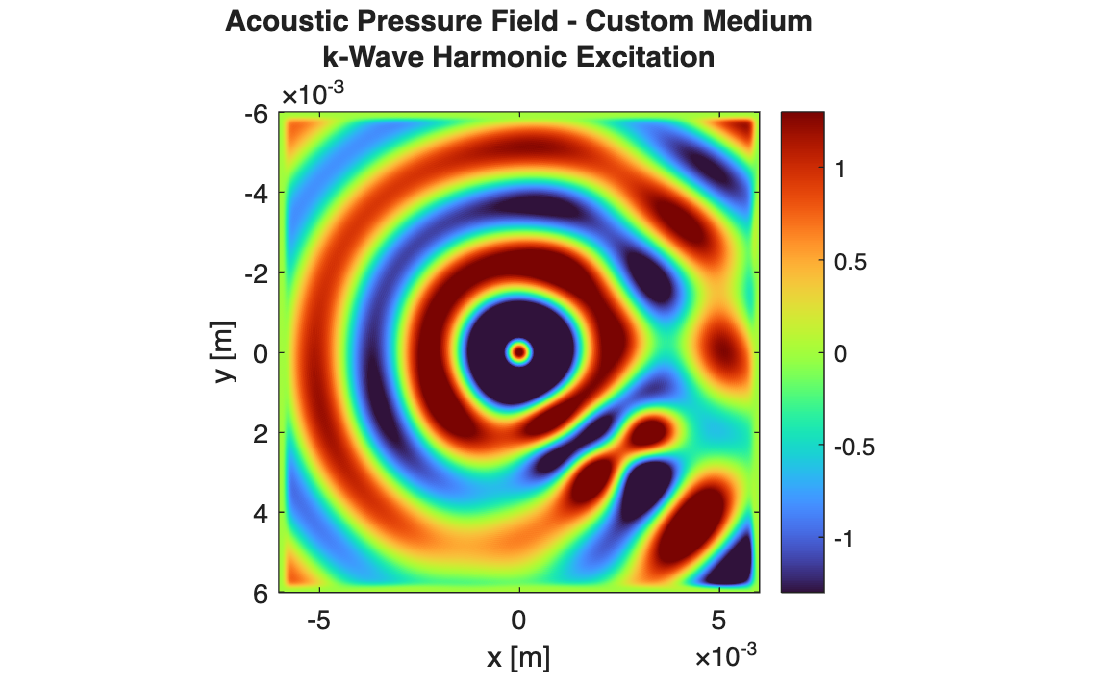

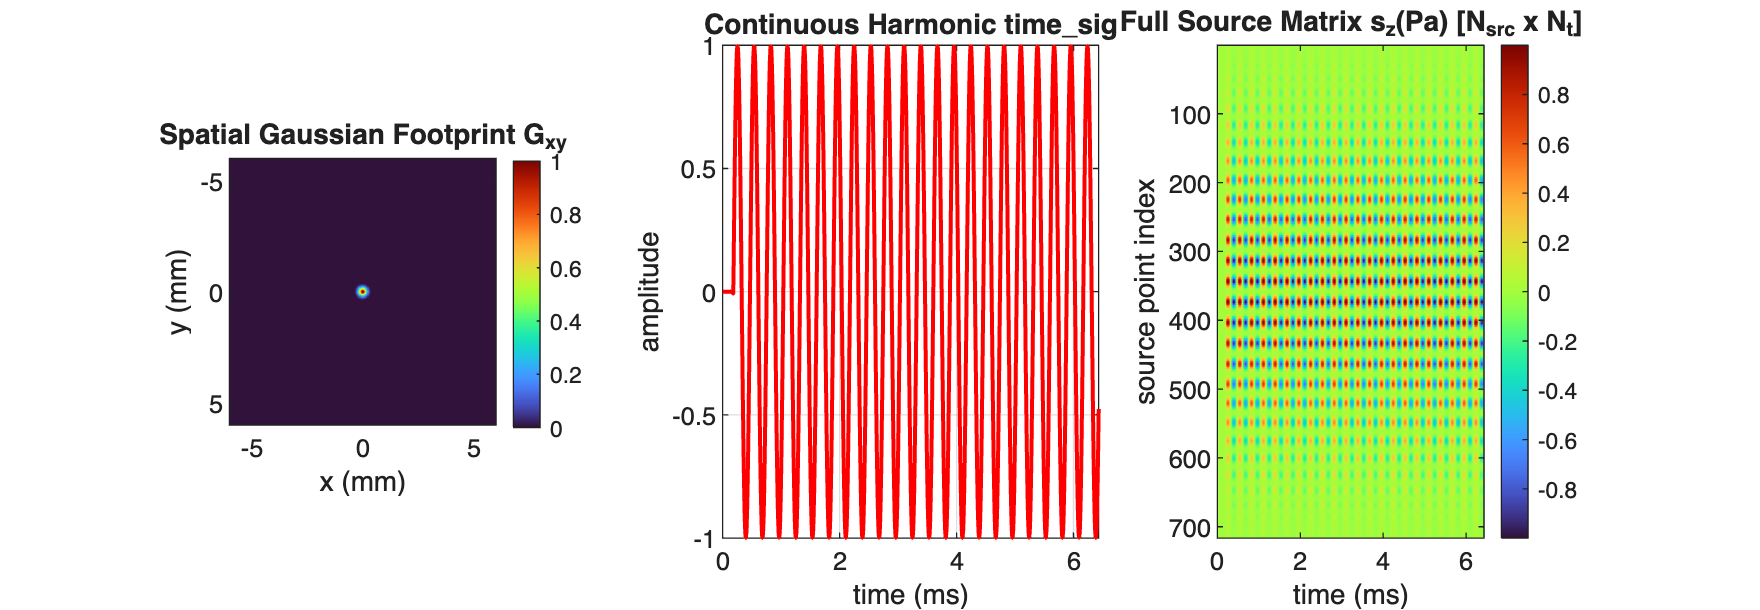

[WaveProp_Vid, x_grid, y_grid, t_grid, GT_SpeedMap] = Wave_Prop_Simulation_v3( ...
    c_medium, Ts_OCT, T_excitation, alpha, N_pulses, A_Peak, ...
    horizontalMin, horizontalMax, verticalMin, verticalMax, ...
    nPoints, N_excitations, prop_type, sim_opts);

#### Ground Truth Phase Speed Values used for Simulation

Display ground truth speed map (cropped):

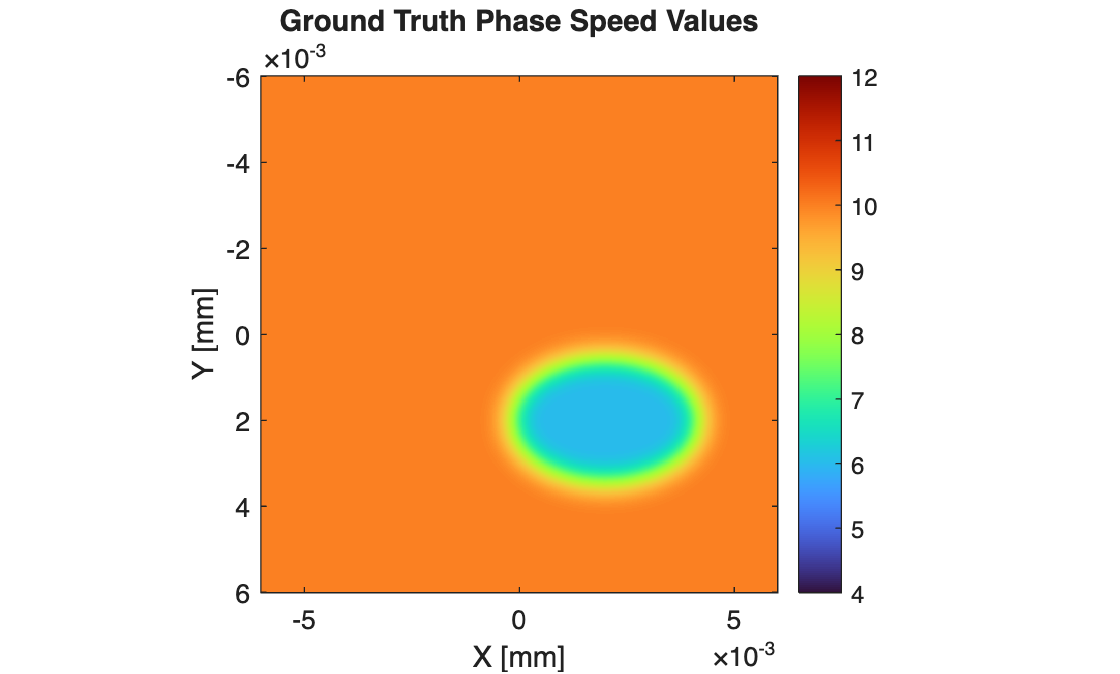

figure, colormap("turbo")
imagesc(x_grid, y_grid,GT_SpeedMap), colorbar, clim([4 12])
axis image;
xlabel('X [mm]'); ylabel('Y [mm]');
title({"Ground Truth Phase Speed Values",""})

#### Space-Time Map of Simulation

And finally, we compute the space-time map for analysis:

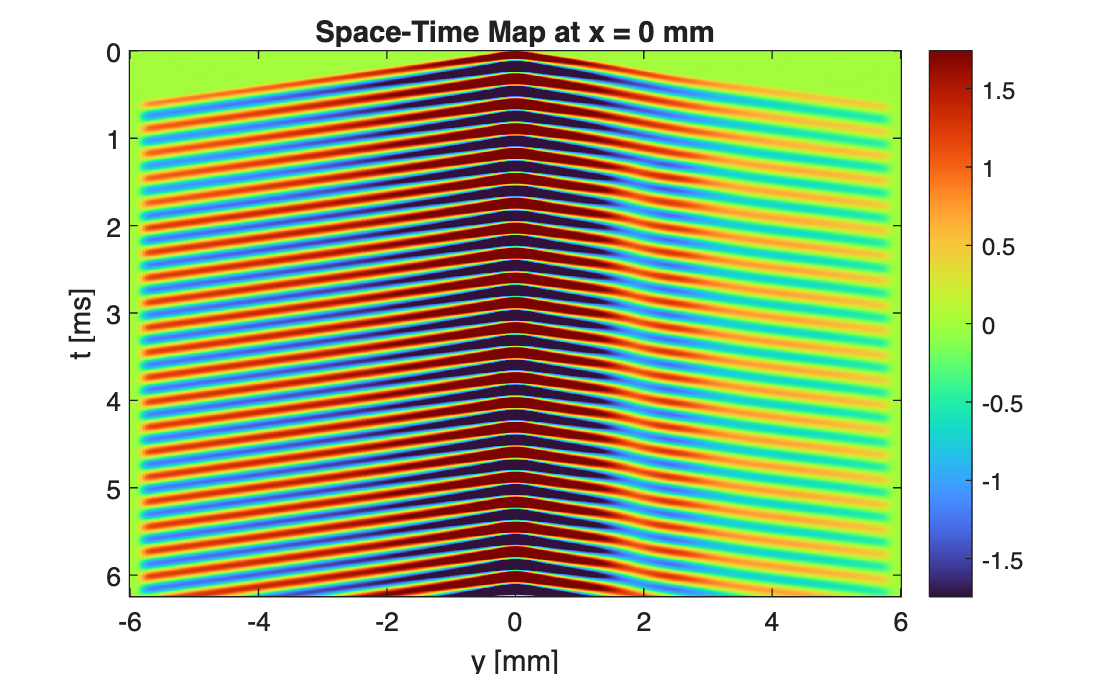

% Set up robust colormap: mean ± 1 sd:
mean_Im_Uz = mean(reshape(WaveProp_Vid,1,[]));
std_Im_Uz = std(reshape(WaveProp_Vid,1,[]));
clim_low = mean_Im_Uz - 2*std_Im_Uz;
clim_high = mean_Im_Uz + 2*std_Im_Uz;
clim_robust = min(abs(clim_low),abs(clim_high));

% Plot Figure:
f_ST = figure(2);
imagesc(x_grid*1e3,t_grid*1e3,squeeze(WaveProp_Vid(:,round(length(y_grid)/2),:)).');
title("Space-Time Map at x = 0 mm")
xlabel("y [mm]")
ylabel("t [ms]")
set(gca,'YDir','reverse'); axis tight;
colormap("turbo"); 
colorbar;
clim([-clim_robust clim_robust])

% ylim([0 2])

Clip to steady-state harmonic wave propagation for SBM protocol:

% Clip to steady-state harmonic wave propagation for SBM mode:
switch protocol_type
    case "SBM"
        start_clipping_sample = floor((0.825*1e-3)/Ts_OCT)-2;
        WaveProp_Vid_Clipped = WaveProp_Vid(:,:,start_clipping_sample:end);
        t_grid_clipped = t_grid(1:end-start_clipping_sample+1);
    otherwise
        WaveProp_Vid_Clipped = WaveProp_Vid;
        t_grid_clipped = t_grid;
end

Show the clipped S-T map:

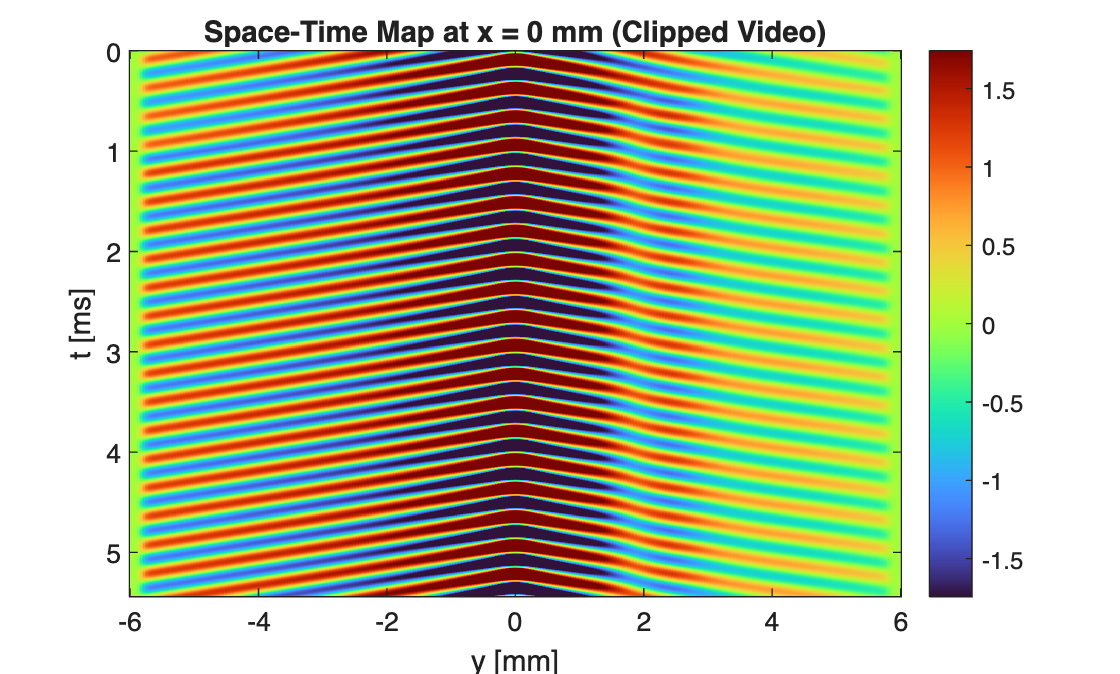

% Plot Figure:
f_ST = figure(2);
imagesc(x_grid*1e3,t_grid_clipped*1e3,squeeze(WaveProp_Vid_Clipped(:,round(length(y_grid)/2),:)).');
title("Space-Time Map at x = 0 mm (Clipped Video)")
xlabel("y [mm]")
ylabel("t [ms]")
set(gca,'YDir','reverse'); axis tight;
colormap("turbo"); 
colorbar;
clim([-clim_robust clim_robust])

## Segmentation Masks: Background and Inclusions

Select masking in accordance to the propagation type (Cylindrical -no inclusions- and Non Cylindrical)

switch prop_type_medium
    case 'Cylindrical'
        MarginPx = 10;
        [Nx, Ny] = size(GT_SpeedMap);
        [xIdx, yIdx] = ndgrid(1:Nx, 1:Ny);
        cx = (Nx + 1)/2;
        cy = (Ny + 1)/2;
        R = min(Nx, Ny)/2 - MarginPx;
        Bkg_Mask = ((xIdx - cx).^2 + (yIdx - cy).^2) <= R^2;
        Inc_Mask = false(size(GT_SpeedMap));
    case 'Non_Cylindrical'
        [Bkg_Mask, Inc_Mask] = Get_Bkg_ROI_Masks( ...
            GT_SpeedMap, 'BgTolFrac', 0.04, 'IncTolFrac', 0.20, 'MarginPx', 10);
    otherwise
        error("Not supported propagation type");
end        

Visualize masks:

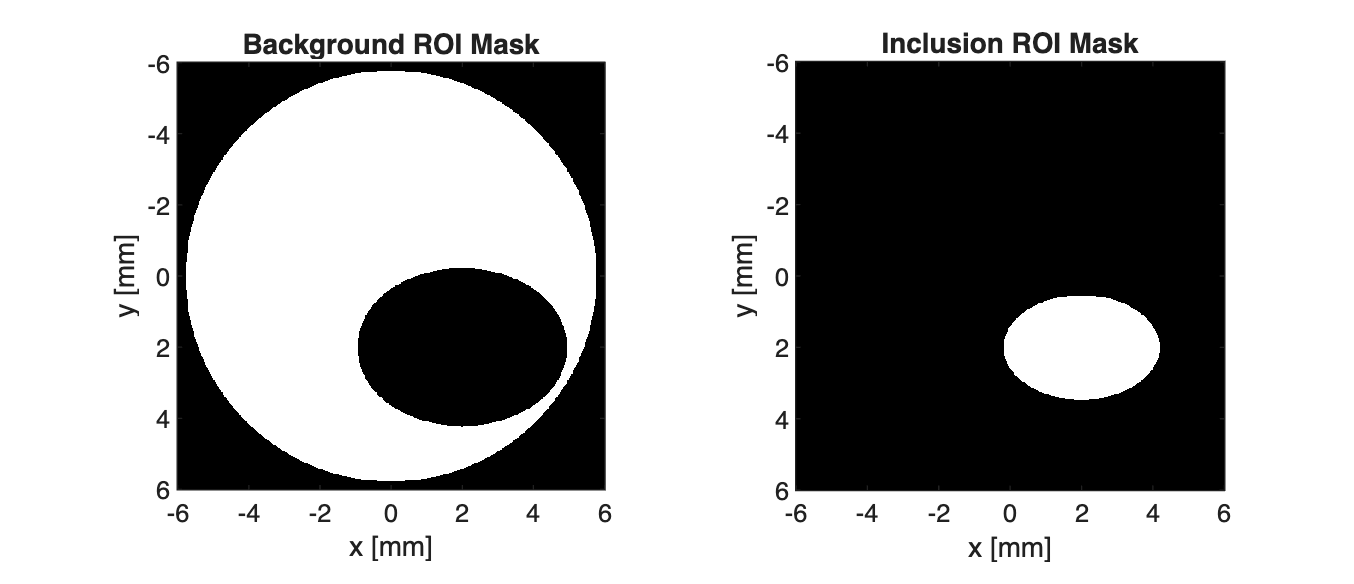

% Background (Bkg) Mask:
figure,
tiledlayout(1,2)
nexttile
imagesc(x_grid*1e3, y_grid*1e3, Bkg_Mask)
set(gca, 'YDir', 'reverse')
axis image
colormap(gca, gray)
title('Background ROI Mask')
xlabel('x [mm]')
ylabel('y [mm]')
xticks(-6:2:6);
% Inclusion Mask:
nexttile
imagesc(x_grid*1e3, y_grid*1e3, Inc_Mask)
set(gca, 'YDir', 'reverse')
axis image
colormap(gca, gray)
title('Inclusion ROI Mask')
xlabel('x [mm]')
ylabel('y [mm]')
xticks(-6:2:6);
set(gcf,"Position",0.6.*[1,1,1128,450]);

Visualize how the masking effect in the Ground Truth speed map:

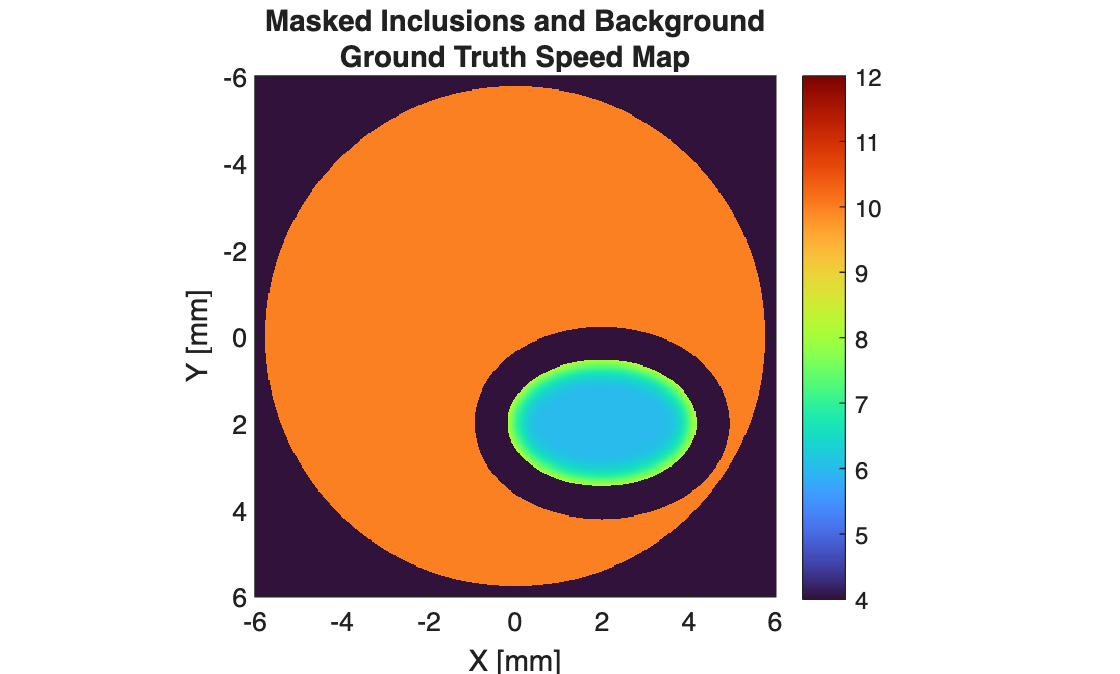

figure,
imagesc(x_grid*1e3, y_grid*1e3,GT_SpeedMap.*Bkg_Mask + GT_SpeedMap.*Inc_Mask);
clim([4 12]);
colormap("turbo"); colorbar;
title({"Masked Inclusions and Background"...
      ,"Ground Truth Speed Map"});
axis image;
xlabel('X [mm]'); ylabel('Y [mm]'); xticks(-6:2:6);

## 2D Phase Gradient Speed Estimation in OG Wave Prop

PhaseGradient2D_FromSims_v3()
Phase-gradient estimator: f_exc=3508.77 Hz, omega0=22046.26 rad/s, Ts_OCT=5e-06 s (fs=200000.00 Hz)
Temporal Hann windowing: 1
Nearest FFT bin: kpos=19 -> f_bin=3512.20 Hz (|f_bin-f_exc|=3.42 Hz)


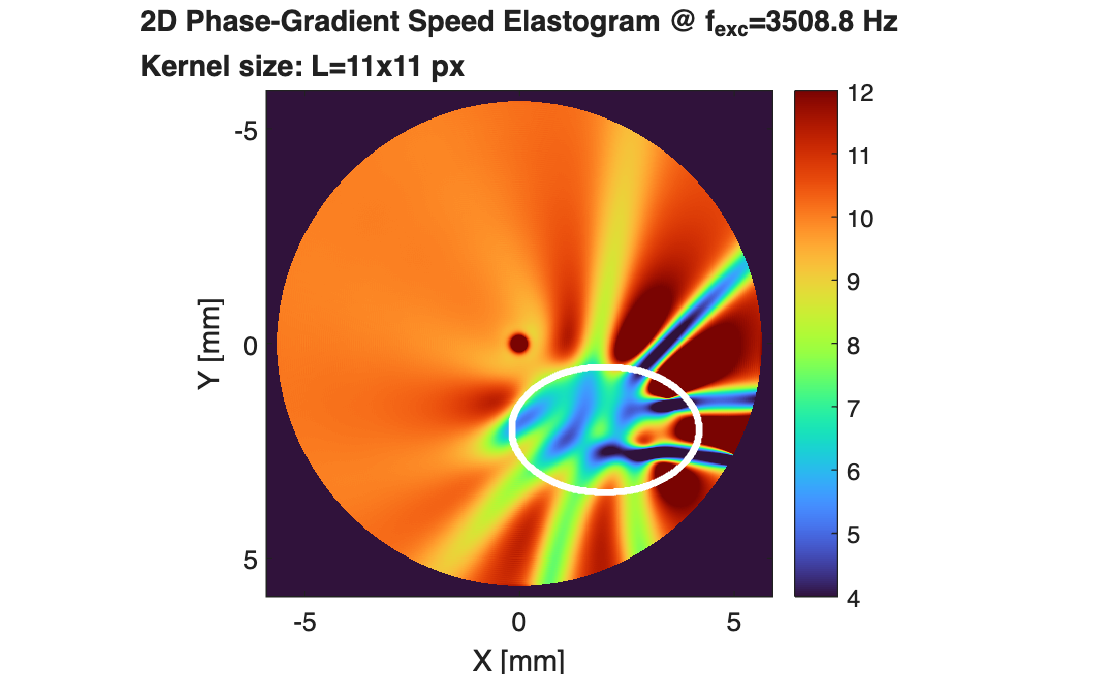

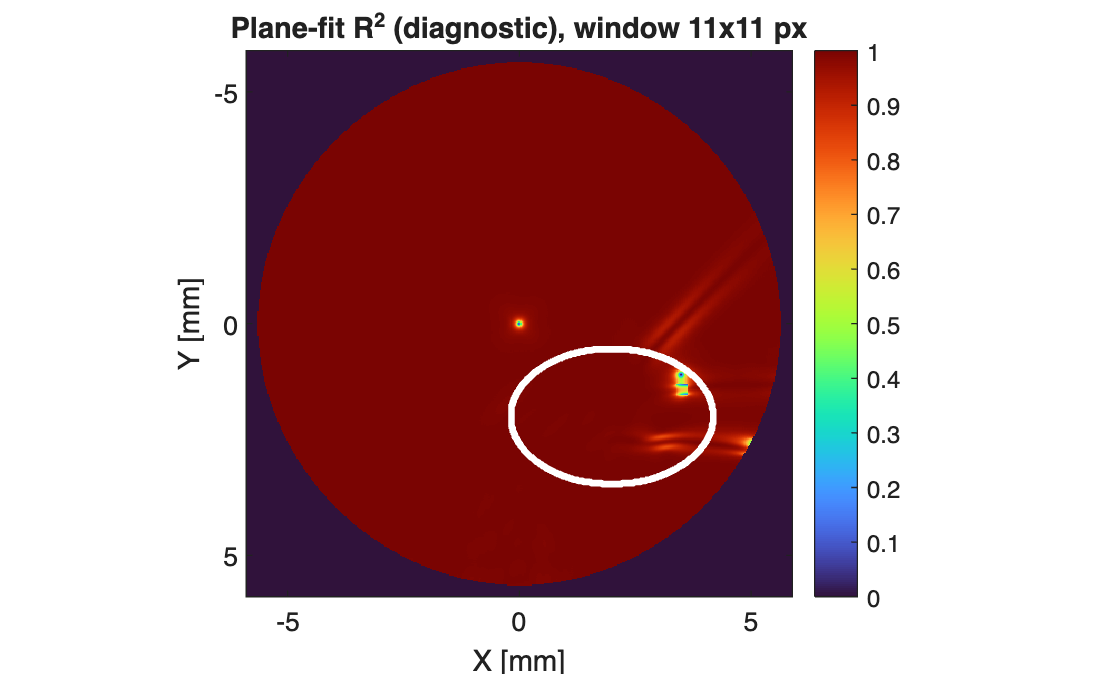

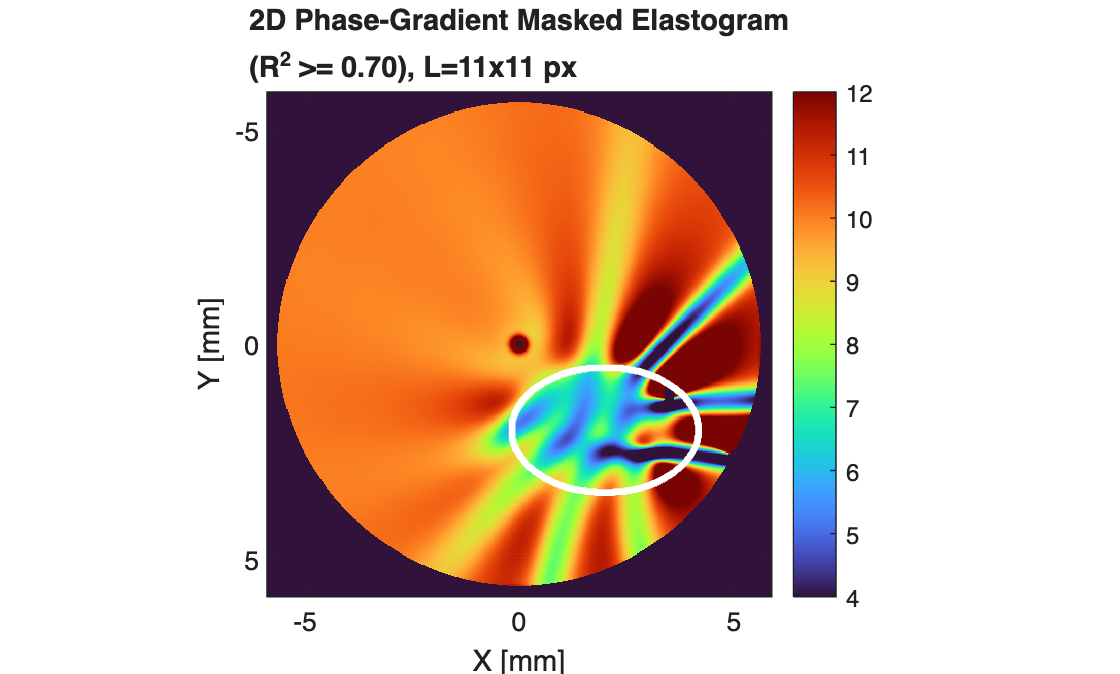

kernel_size = 11; % L x L window for estimation
applyTemporalWindow = true;
% Color limits for 2D PG estimation:
clim_limits_2DPG = [4 12];

% Perform Phase Speed Estimation in WaveProp vid:
[Elastogram_OGWaveProp, R2_map_OGWaveProp, Elastogram_Masked_OGWaveProp, ...
 Xcrop_mm_OGWP, Ycrop_mm_OGWP, Complex_Field_Vz_OGWP, ...
 Inc_Mask_Crop_OGWP, Bkg_Mask_Crop_OGWP, Kx_OGWP, Ky_OGWP, Kmag_OGWP] = ...
    PhaseGradient2D_FromSims_v3( ...
        WaveProp_Vid_Clipped, Inc_Mask, Bkg_Mask,...
        kernel_size, Ts_OCT, T_excitation, ...
        horizontalMin, horizontalMax, verticalMin, verticalMax, ...
        applyTemporalWindow, clim_limits_2DPG);

Plot the k-vector field on top of the multimeridian pattern for reference, and let's set the pattern to 8 meridians:

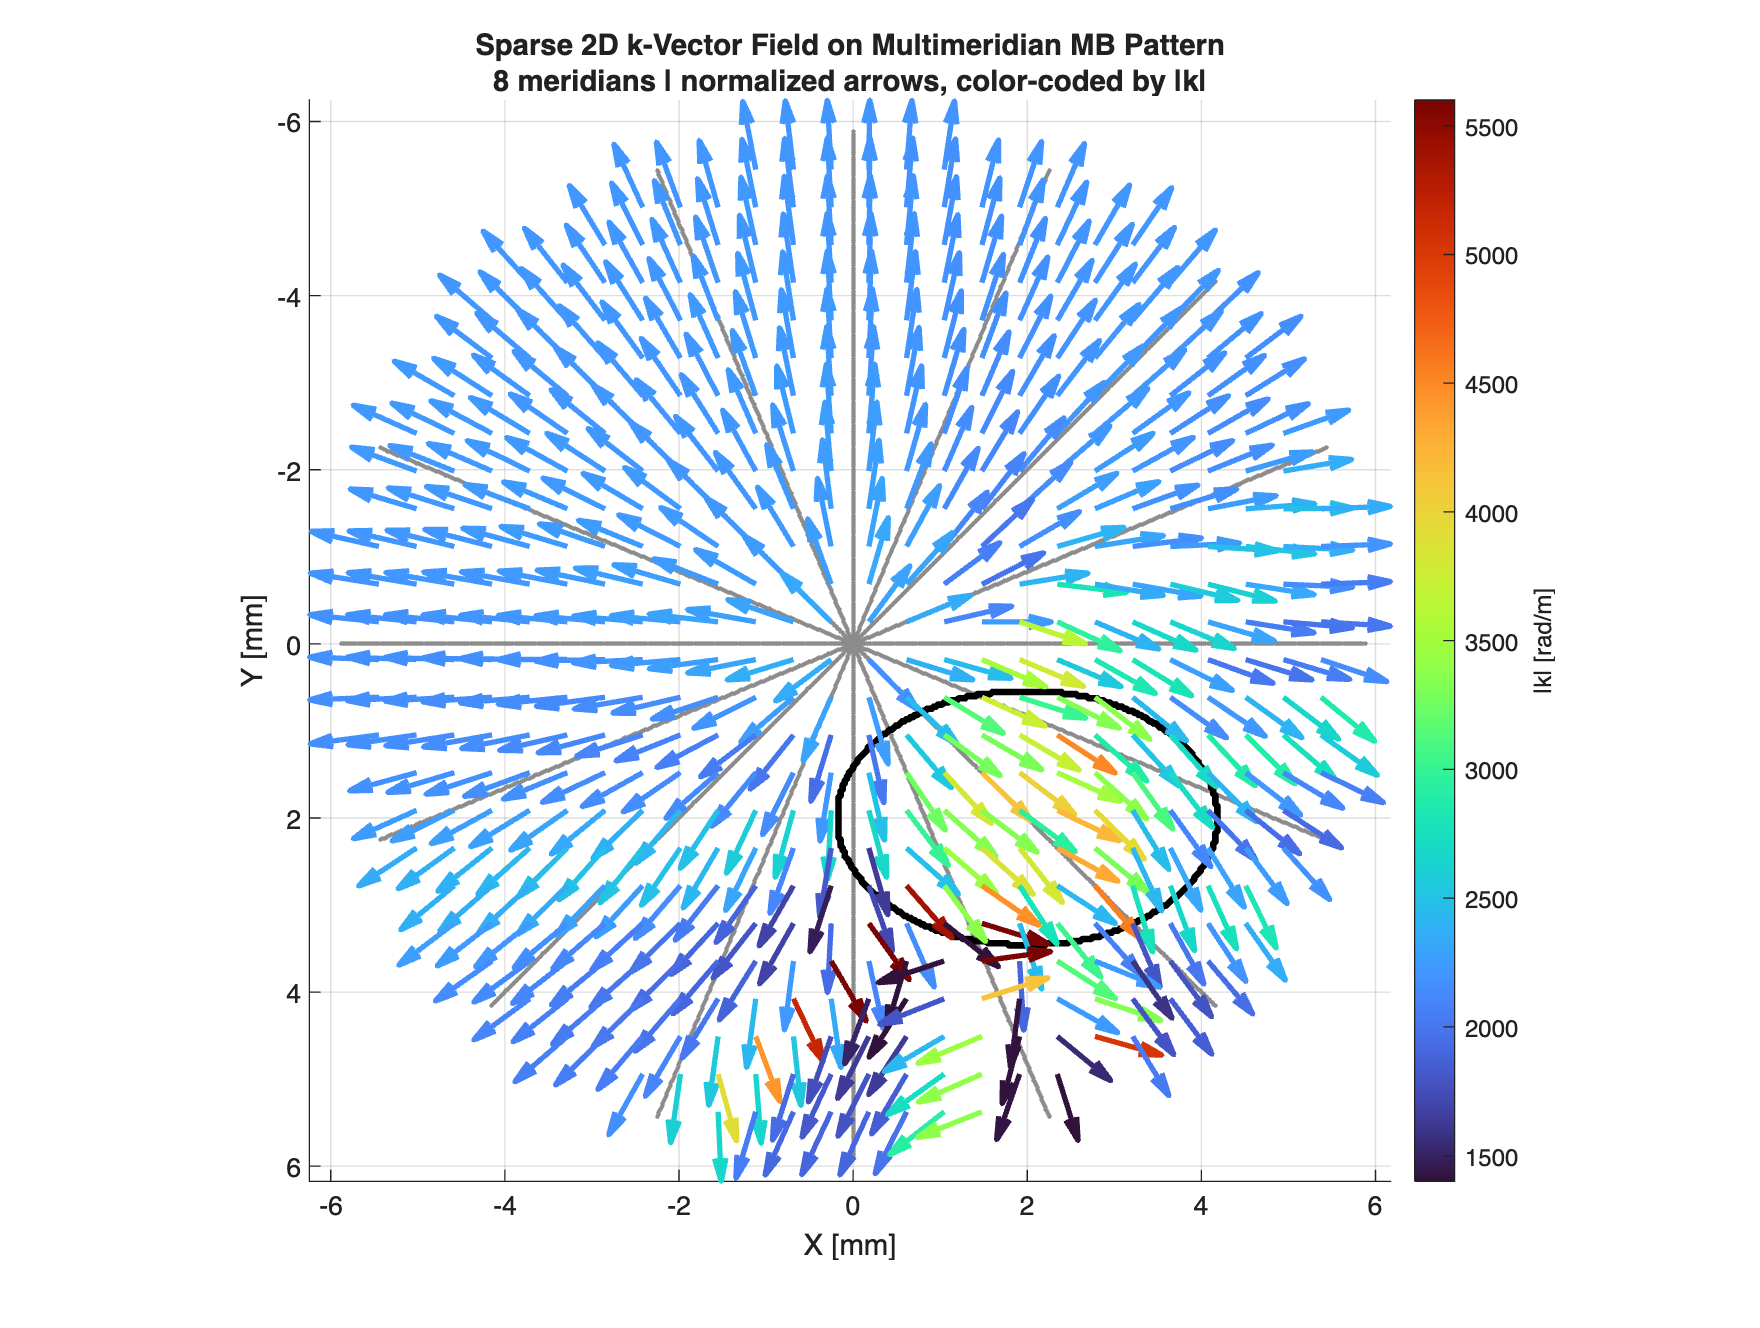

kplot_opts = struct();
kplot_opts.vectorStride = 18;
kplot_opts.vectorScale_mm = 0.8;
kplot_opts.forceOutward = true;
kplot_opts.sourceOrigin_mm = [0 0];
kplot_opts.kClim = [1400 5600]; % [rad/m]

Reference_Number_Meridians = 8;

plot_KVectorField_On_MBPattern( ...
    Kx_OGWP, Ky_OGWP, Inc_Mask_Crop_OGWP, ...
    Reference_Number_Meridians, Xcrop_mm_OGWP, Ycrop_mm_OGWP, ...
    kplot_opts);

## Definition of Acquisition Vectors from the newly proposed Synchronized BM Mode Protocol (SBM)

Based on GalvoFuncOCE function implemented in Keralastic's system (PhS Swept-Source OCT)

### Number of Frames and Excitation Period Selection

Before continuing further is important to note the fact that the universal clock of the simulation and of the acquisition in general is the OCT sampling rate, which in this case is 200 kHz, or its equivalent sampling period of 5 $\mu s$. This in turn means that whenever we add the delay between the start of the frame and the acquisition trigger, this delay must be an integer multiple of that sampling period of 5 $\mu s$, otherwise we'll have an accumulating error from rounding to the number of samples. That means that the excitation frequency cannot be chosen arbitrarily, neither does the number of BM frames that we'll acquire, since the phase-step that grows every frame, let's call it $\tau$, depends on the number of frames and the excitation period:


$$\tau = \frac{\text{Excitation Period}}{\text{Number of BM Frames}} \, \space \left[ s \right]$$


And therefore, expressed as a function of OCT samples:


$$\tau_N = \frac{\text{Excitation Period}}{\text{Number of BM Frames} \times \text{OCT Sampling Period}} \, \space \left[ \text{OCT Samples} \right]$$


Where $\tau_N$ must be an integer number. Therefore we'll have discrete number of frames, which are the divisors of the excitation period in microseconds over 5, that are possible to choose:

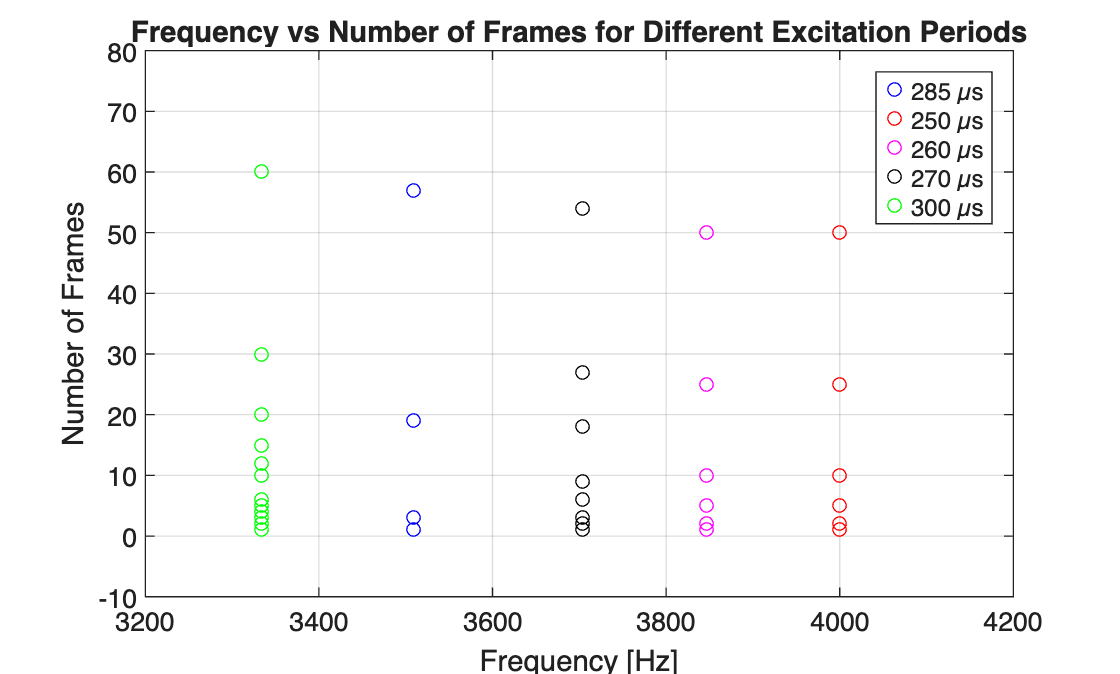

numFrames_vs_FreqMap()

Based on this, for the previously selected excitation period of 285 µs we can define the following number of BM frames:

nFrames = 57; % Number of BM Frames

### User Parameters/Inputs

% Ts_OCT = 5e-6;         % [s] A-line period (200 kHz)
% horizontalMin = -6; horizontalMax = 6;
% verticalMin = -6; verticalMax = 6;
% M_repetitions = 200; % kept for compatibility

% Defined at the beginning of the script:
% nAscans = 57*3; % A-lines per horizontal line
% nBscans = 57*3; % number of horizontal lines, 
% must be an odd number to go through the middle

% Amplitude of SyncSamples:
% SyncAmp = 1;

% TTL pulse widths (in OCT samples)
ExcPulseWidth = 10;   % excitation TTL width (samples)
AcqPulseWidth = 10;   % acquisition TTL width (samples)

% delay after excitation before scanning starts (and before acquisition train)
startDelay_samples = 47;   % small delay so excitation rising edge leads acquisition/scan

% Phase stepping: how many OCT samples to shift acquisition per frame
phaseStepSamples = 4; %((T_excitation/nFrames)/Ts_OCT); -> So that we get 4 periods by taking 57 frames
% phaseStepSamples = 0;

% % Resolution of the transition turns:
% nTurnSamples = 57;     % number of samples to discretize each transition turn

### Generation of Acquisition Vectors

Using the `AcqVectors_SBM` function, we compute the acquisition vectors that correspond with the given user inputs for the SBM protocol:

samplesPerExcPeriod = 57 (T_exc = 0.285 ms)
phaseStepSamples = 4
Built waveform timeline: total samples = 383154 (nFrames=57), Nsingle=6441, transition=114
Total acquisition time: 1915.77 ms

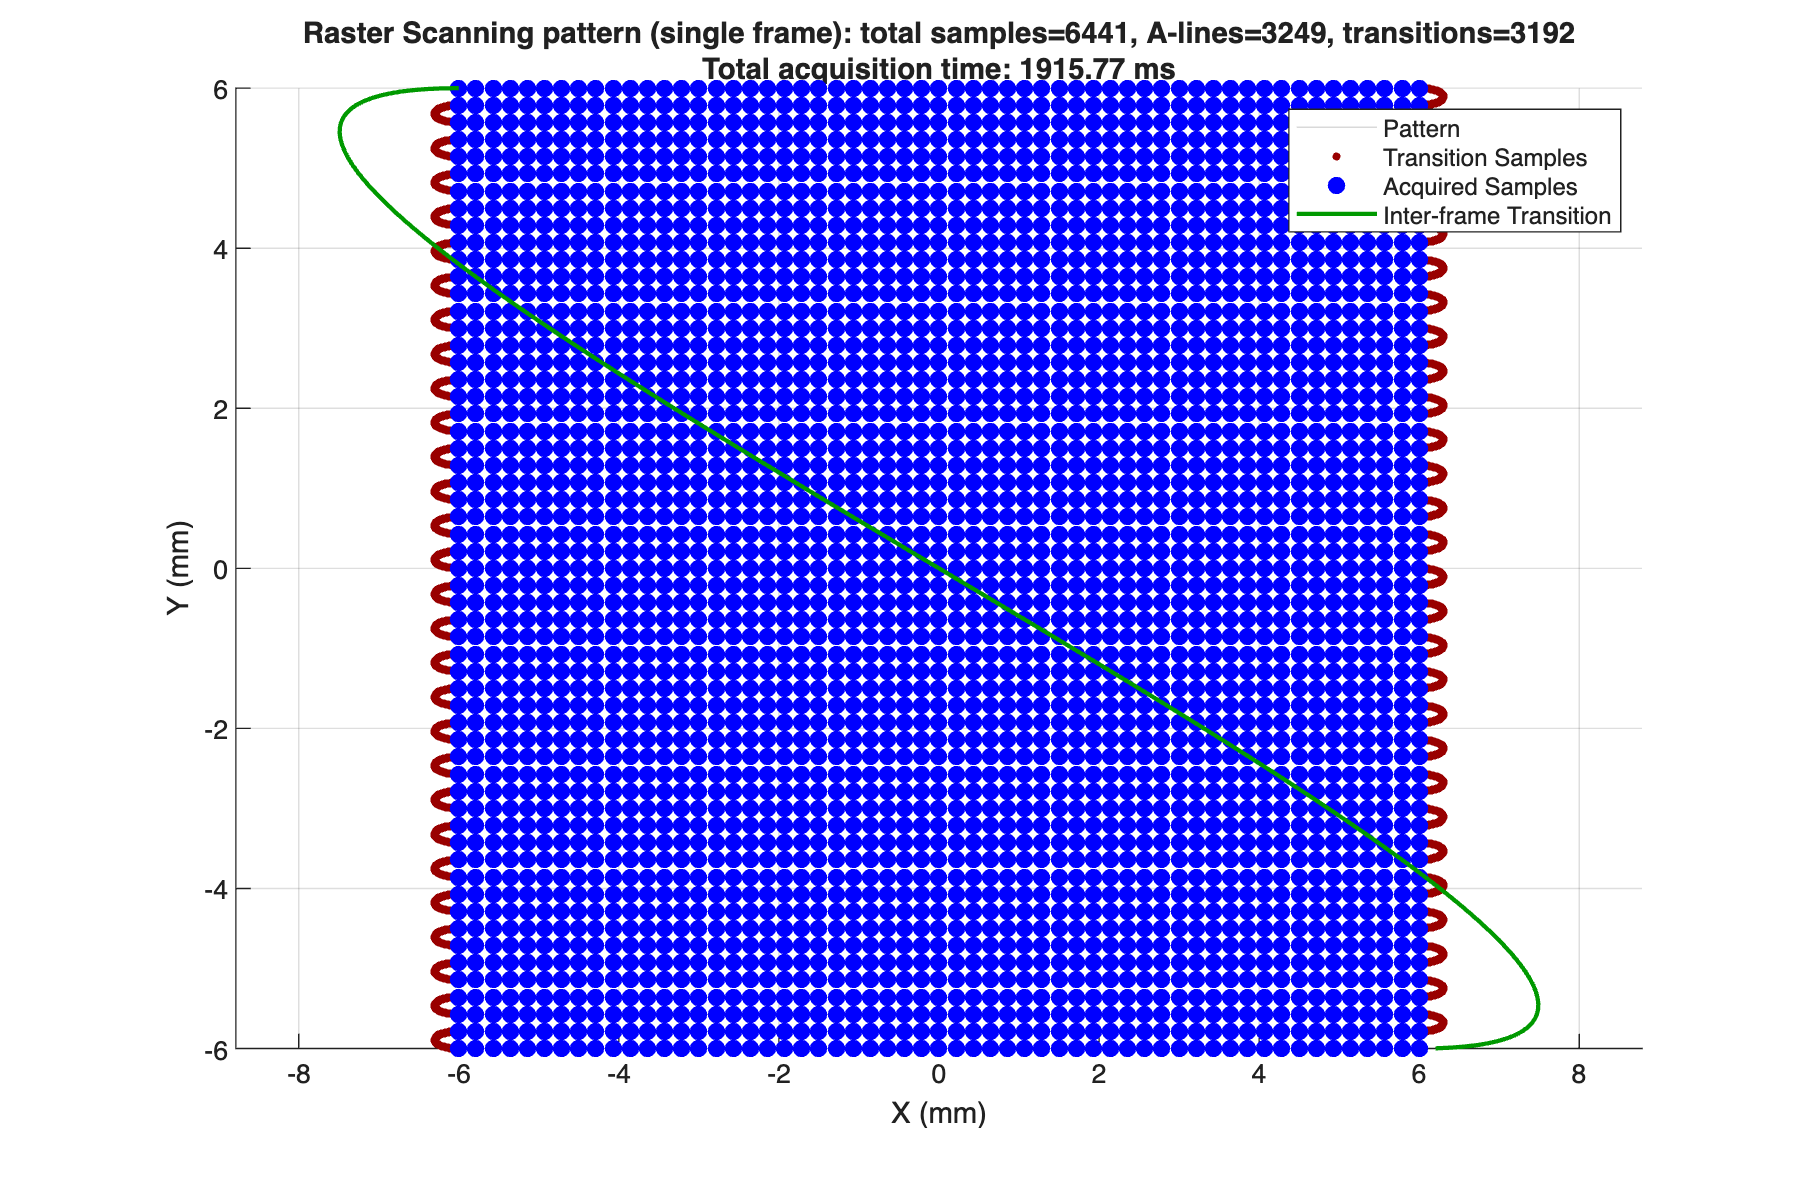

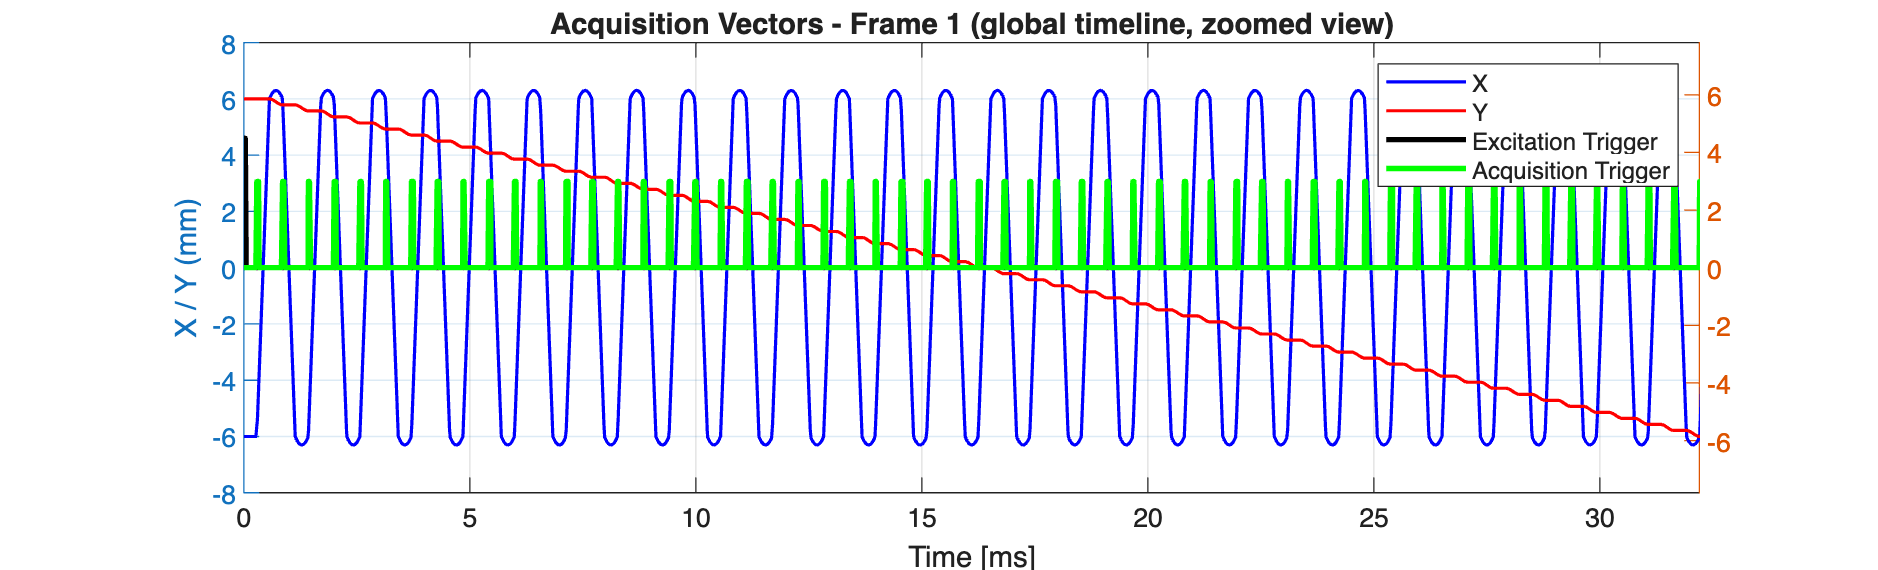

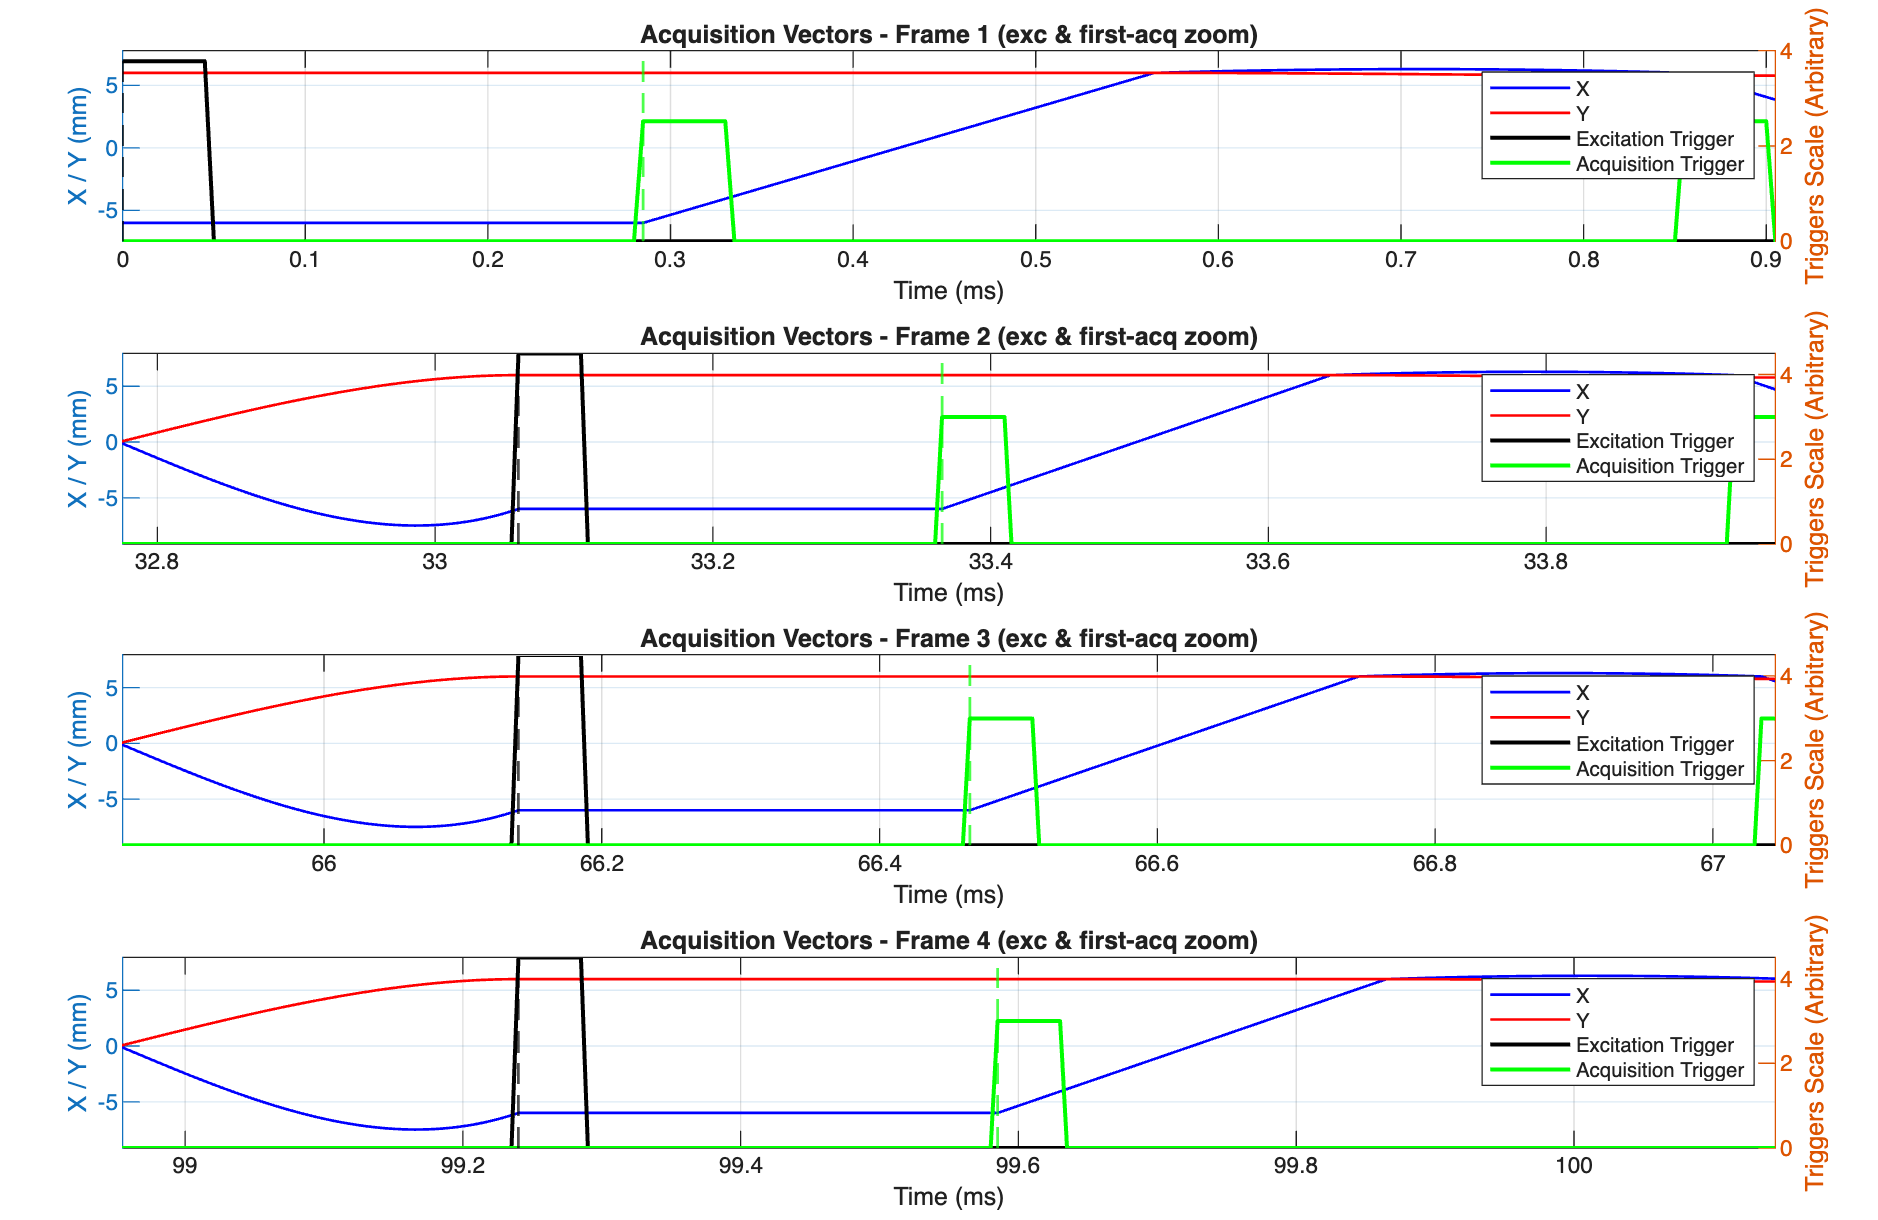

[Exc_Trigger,Acq_Trigger,GalvoX,GalvoY,Exc_aux] = AcqVectors_SBM(horizontalMin,horizontalMax,verticalMin,...
                                                    verticalMax,nAscans,nBscans,nFrames,...
                                                    startDelay_samples,nTurnSamples,AcqPulseWidth,...
                                                    ExcPulseWidth,T_excitation,Ts_OCT,phaseStepSamples);

### Quick Manual Diagnostics

Time vector for the acquisition:

t_acqvecs = 0:Ts_OCT:(length(GalvoX)-1)*Ts_OCT;

Control of xlims (in ms) in order to visualize desired region:

xlim_lowbound = 0; % [ms]
xlim_upbound = 165; % [ms]

Galvo X and Galvo Y in the Same Figure:

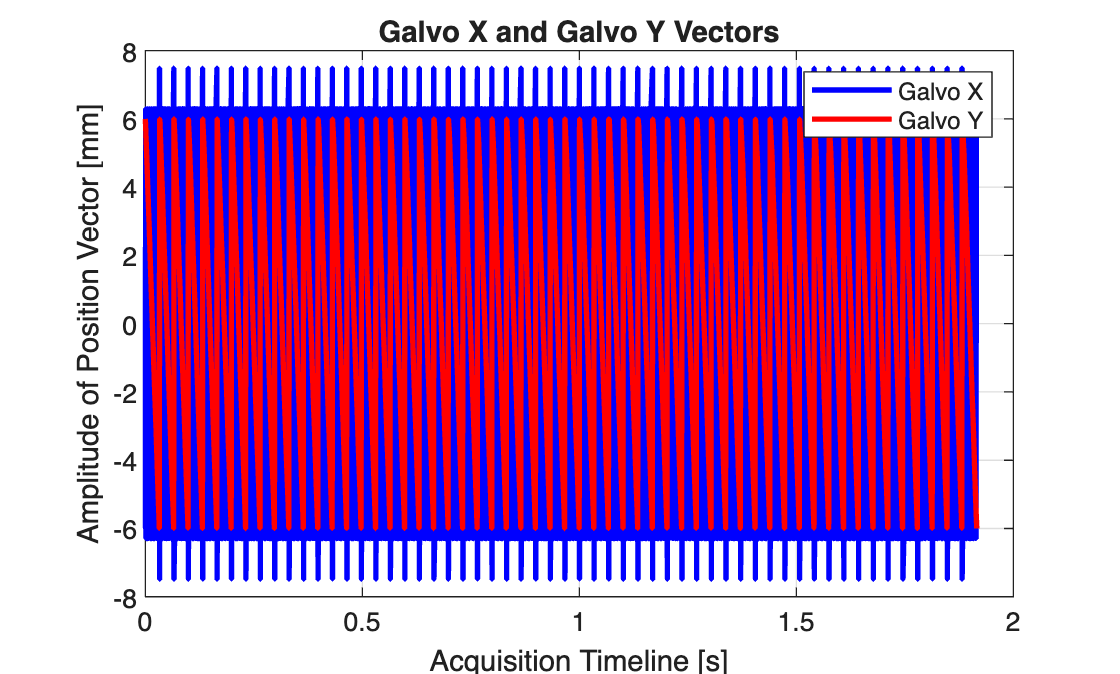

figure,
plot(t_acqvecs,GalvoX,'LineStyle','-','LineWidth',2,'Color','Blue');
hold on;
plot(t_acqvecs,GalvoY,'LineStyle','-','LineWidth',2,'Color','Red');
title("Galvo X and Galvo Y Vectors");
xlabel("Acquisition Timeline [s]");
ylabel("Amplitude of Position Vector [mm]");
legend("Galvo X","Galvo Y");
grid on;

% % From region limited by user input:
% xlim([xlim_lowbound xlim_upbound]*1e-3);

Plot of 4 vectors in tiled layout:

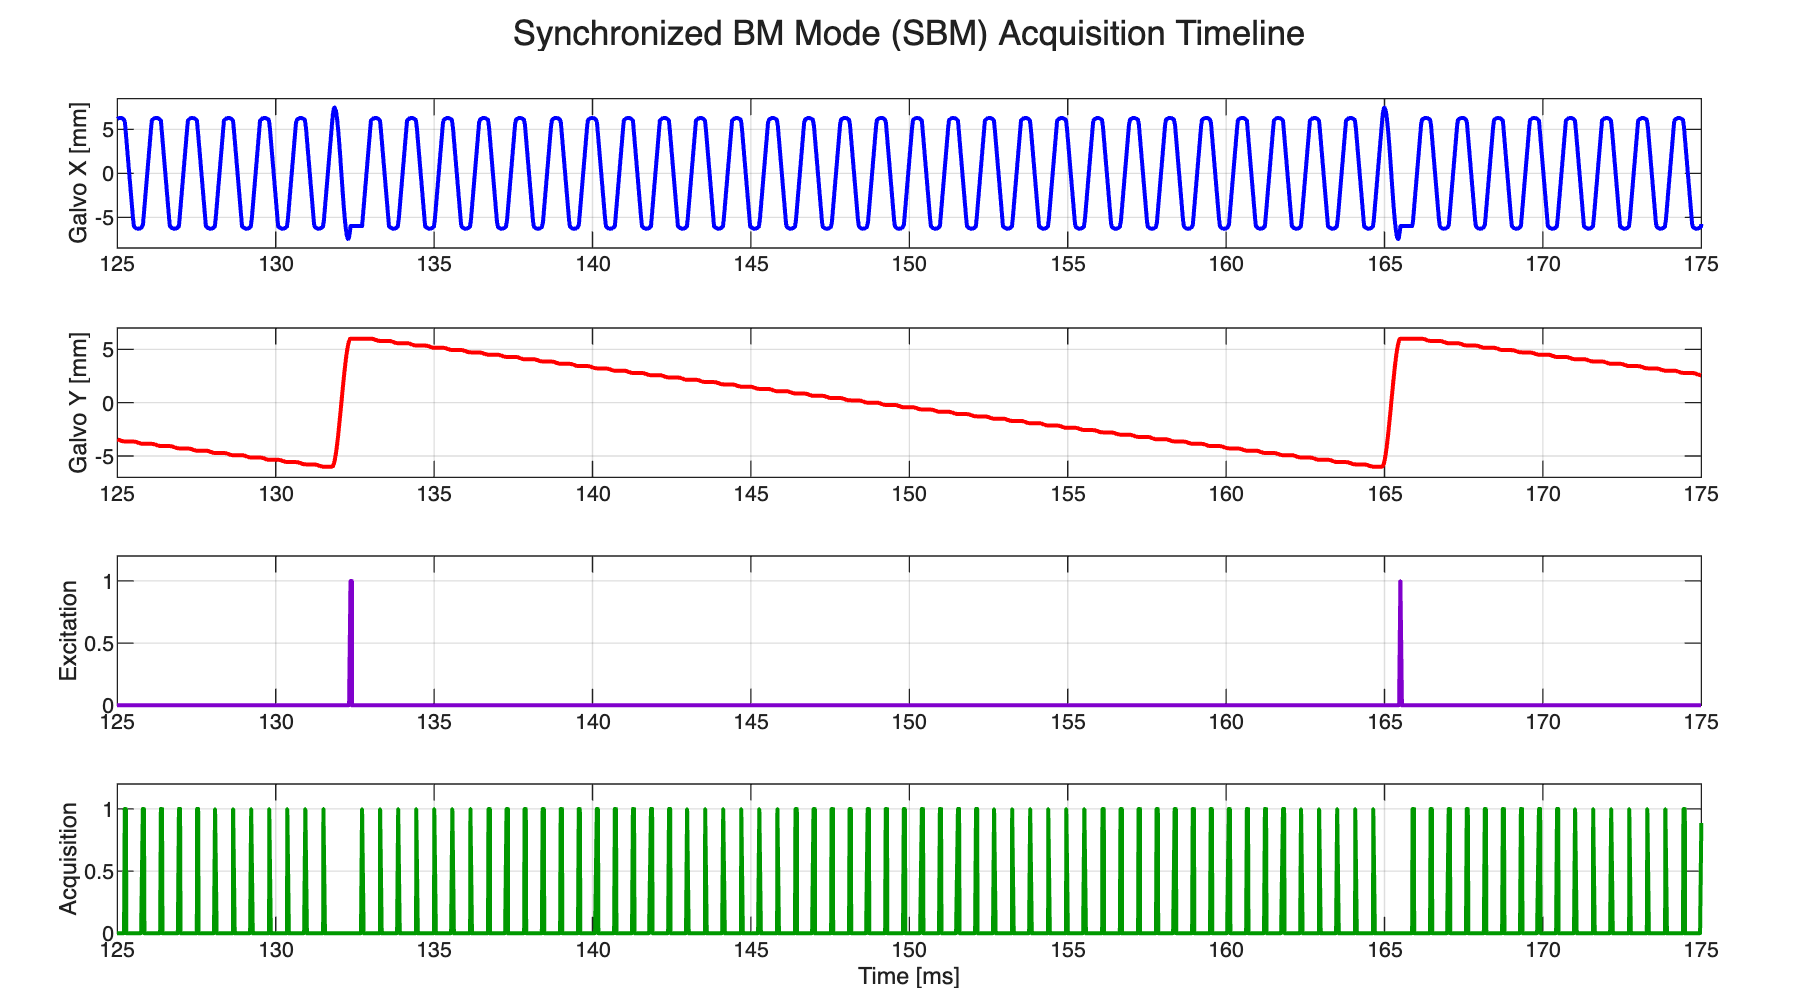

% ===================== INPUT =====================
% [Exc_Trigger,Acq_Trigger,GalvoX,GalvoY] already computed

% Time vector
N = length(GalvoX);
t = (0:N-1) * Ts_OCT * 1e3; % [ms]

% Normalize triggers
Exc_plot = Exc_aux / max(Exc_aux);
Acq_plot = Acq_Trigger / max(Acq_Trigger);

% ===================== FIGURE =====================
figure('Color','w','Position',[100 100 900 500]);

tiledlayout(4,1,'TileSpacing','compact','Padding','compact');

% ===================== GALVO X =====================
nexttile;
plot(t, GalvoX, 'b', 'LineWidth', 1.5);
ylabel('Galvo X [mm]');
ylim([min(GalvoX)-1 max(GalvoX)+1]);
% xlim([1250 1300]);
xlim_start_t_ms = 125;
xlim([xlim_start_t_ms xlim_start_t_ms+50]);
grid on;

% ===================== GALVO Y =====================
nexttile;
plot(t, GalvoY, 'r', 'LineWidth', 1.5);
ylabel('Galvo Y [mm]');
ylim([min(GalvoY)-1 max(GalvoY)+1]);
% xlim([1250 1300]);
xlim([xlim_start_t_ms xlim_start_t_ms+50]);
grid on;

% ===================== EXCITATION TRIGGER =====================
nexttile;
plot(t, Exc_plot, 'Color',[0.5 0 0.8], 'LineWidth', 1.5);
ylabel('Excitation');
ylim([0 1.2]);
% xlim([1250 1300]);
xlim([xlim_start_t_ms xlim_start_t_ms+50]);
grid on;

% ===================== ACQUISITION TRIGGER =====================
nexttile;
plot(t, Acq_plot, 'Color',[0 0.6 0], 'LineWidth', 1.5);
ylabel('Acquisition');
xlabel('Time [ms]');
ylim([0 1.2]);
% xlim([1250 1300]);
xlim([xlim_start_t_ms xlim_start_t_ms+50]);
grid on;

% ===================== GLOBAL =====================
sgtitle('Synchronized BM Mode (SBM) Acquisition Timeline');

% Link axes (still useful for zoom consistency)
linkaxes(findall(gcf,'Type','axes'),'x');

## Sampling Simulation

Now that we have our acquisition vectors, let's sample the wave-propagation video in accordance to them. 

### Sampling Obeying Acquisition Vectors

This is the ideal version (no saccades), therefore, we'll only pass to our simulation engine the relevant parameters)

[SampledFrames_vis, SampledFrames_raw] = SamplingSim_fromAcqVecs(WaveProp_Vid_Clipped,x_grid,...
    y_grid,t_grid_clipped,GalvoX,GalvoY,Acq_Trigger,Exc_aux,nFrames,nAscans,nBscans,nTurnSamples,T_excitation,Ts_OCT);

Sampling done: produced SampledFrames_raw (57x57x57) and SampledFrames_vis (57x57x57)


### Video of Sampled Frames

Obtain color limits for video

% Set up robust colormap: mean ± 1 sd:
mean_SampledFrames_vis = mean(reshape(SampledFrames_vis,1,[]),"omitnan");
std_SampledFrames_vis = std(reshape(SampledFrames_vis,1,[]),"omitnan");
clim_low = mean_SampledFrames_vis - 2*std_SampledFrames_vis;
clim_high = mean_SampledFrames_vis + 2*std_SampledFrames_vis;
clim_robust = min(abs(clim_low),abs(clim_high));
% clim_robust = 2;

Obtain video:

% Get video:
figure,
for i = 1:size(SampledFrames_vis,3)

    current_frame = squeeze(SampledFrames_vis(:,:,i));
    
    % imagesc(linspace(GalvoX(1),GalvoX(end),nAscans),linspace(GalvoY(1),GalvoY(end),nBscans),current_frame)
    imagesc(linspace(verticalMin,verticalMax,nBscans),linspace(horizontalMin,horizontalMax,nAscans),current_frame)
    axis image; set(gca,'YDir','normal');

    title({"Corrected-Orientation Spatial Frames that Obey",sprintf("Synchronized BM Mode (SBM). Frame %d",i)});
    xticks(-6:2:6)
    xlabel("X Axis [mm]")
    ylabel("Y Axis [mm]")
    set(gca,'YDir','normal'); axis tight;
    clim([-clim_robust clim_robust])
    colormap("turbo")
    colorbar
    %drawnow
    pause(0.1)
end

#### Video or Raw Frames

% % Get video:
% figure,
% for i = 1:size(SampledFrames_raw,3)
% 
%     current_frame = squeeze(SampledFrames_raw(:,:,i));
% 
%     % imagesc(linspace(GalvoX(1),GalvoX(end),nAscans),linspace(GalvoY(1),GalvoY(end),nBscans),current_frame)
%     imagesc(linspace(verticalMin,verticalMax,nBscans),linspace(horizontalMin,horizontalMax,nAscans),current_frame)
%     axis image; set(gca,'YDir','normal');
% 
%     title({"Raw Spatial Frames (No Serpentine Compensation)",sprintf("Synchronized BM Mode (SBM). Frame %d",i)});
%     xticks(-6:2:6)
%     xlabel("X Axis [mm]")
%     ylabel("Y Axis [mm]")
%     set(gca,'YDir','normal'); axis tight;
%     clim([-clim_robust clim_robust])
%     colormap("turbo")
%     colorbar
%     %drawnow
%     pause(0.1)
% end

### Space-Time map of Sampled Frames

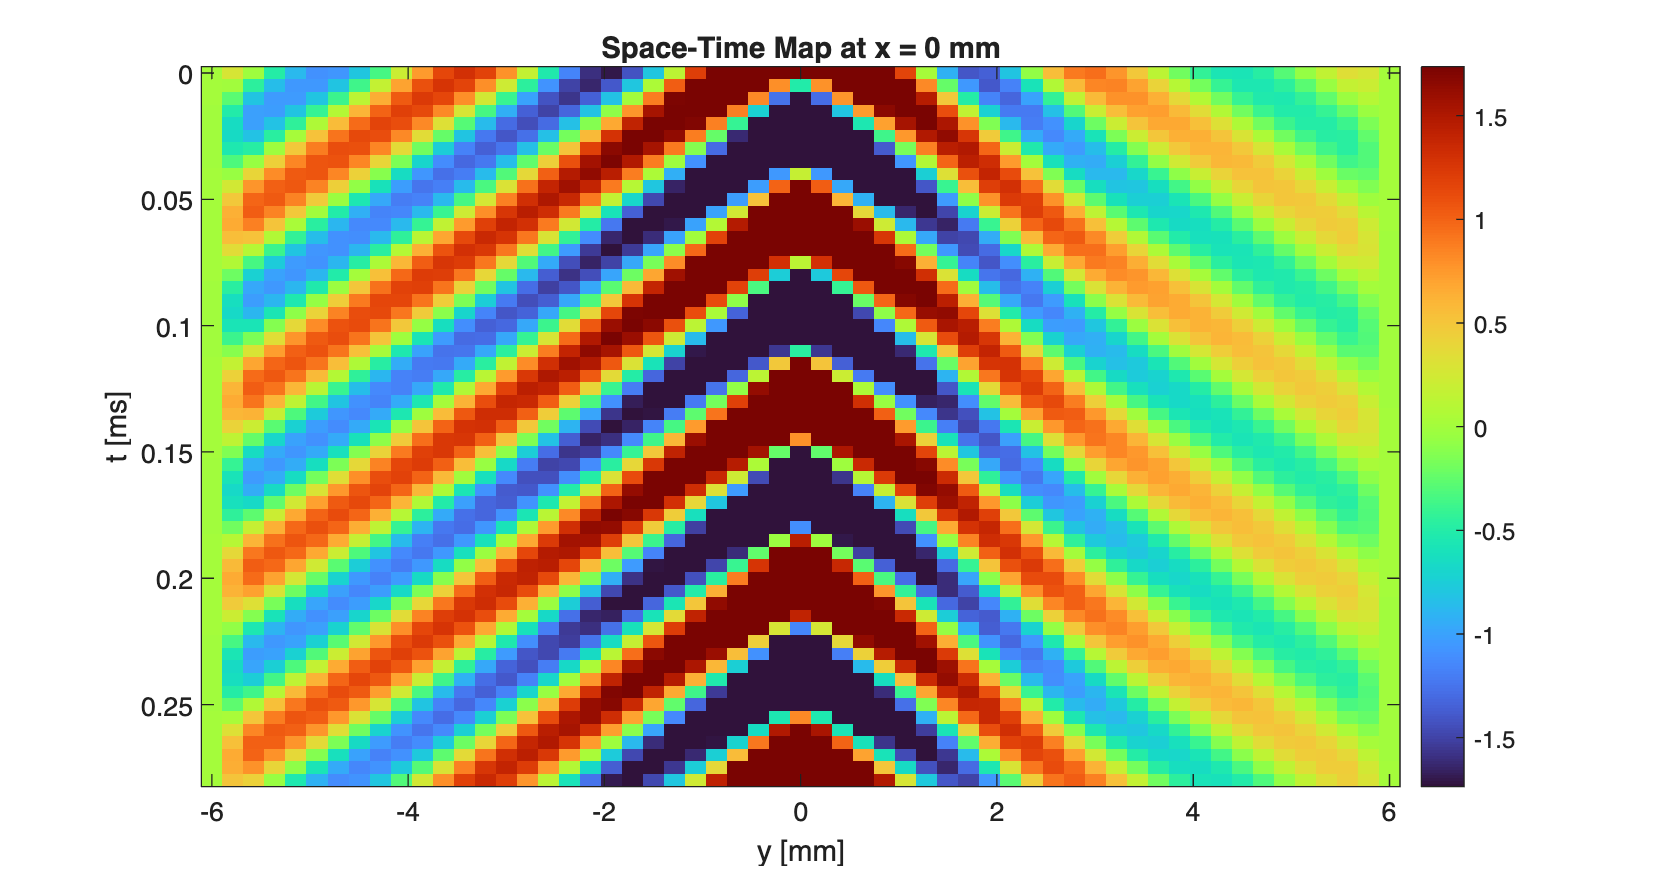

figure('Name','S-T from SBM Frames','Units','normalized','Position',[0.18 0.12 0.55 0.45]);
imagesc(x_grid*1e3,(0:Ts_OCT:(nFrames-1)*Ts_OCT)*1e3,transpose(flipud(squeeze(SampledFrames_vis(:,round(size(SampledFrames_vis,2)/2),:)))));
title("Space-Time Map at x = 0 mm")
xlabel("y [mm]")
ylabel("t [ms]")
set(gca,'YDir','reverse'); axis tight;
colormap("turbo"); 
colorbar;
clim([-clim_robust clim_robust])

## Recovery Function

This function compensates for the induced doppler shifts produced by the continuous scanning of the laser in the BM spatial pattern, effectively compensating the accumulated phase throughout the entire acquisition.

### Function Execution

[Acq_Phase_Matrix, Recovered_Frames] = Recovery_fromSampledFrames_SBM(...
    nTurnSamples, T_excitation,...
    Ts_OCT, nFrames, SampledFrames_raw,phaseStepSamples);
Recovered_Frames = flipud(Recovered_Frames);

#### Video:

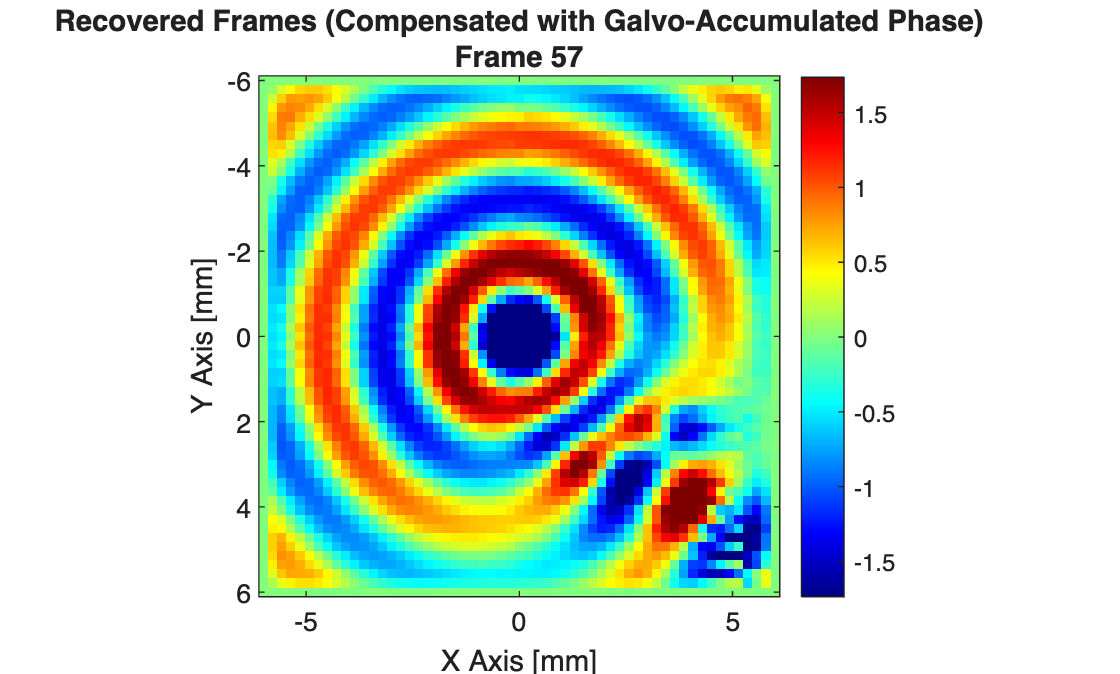

figure,

% Get video:
for i = 1:nFrames

    current_frame_recov = squeeze(Recovered_Frames(:,:,i));

    % imagesc(linspace(GalvoX(1),GalvoX(end),nAscans),linspace(GalvoY(1),GalvoY(end),nBscans),current_frame)
    imagesc(linspace(verticalMin,verticalMax,nBscans),linspace(horizontalMin,horizontalMax,nAscans),current_frame_recov)

    title({"Recovered Frames (Compensated with Galvo-Accumulated Phase)",sprintf("Frame %d",i)})
    xlabel("X Axis [mm]")
    ylabel("Y Axis [mm]")
    set(gca,'YDir','reverse'); axis image;
    colormap("jet")
    % colormap("jet")
    clim([-clim_robust clim_robust])
    colorbar
    %drawnow
    pause(0.1)
end 

#### Accumulated Phase from Spatio-temporal Pattern:

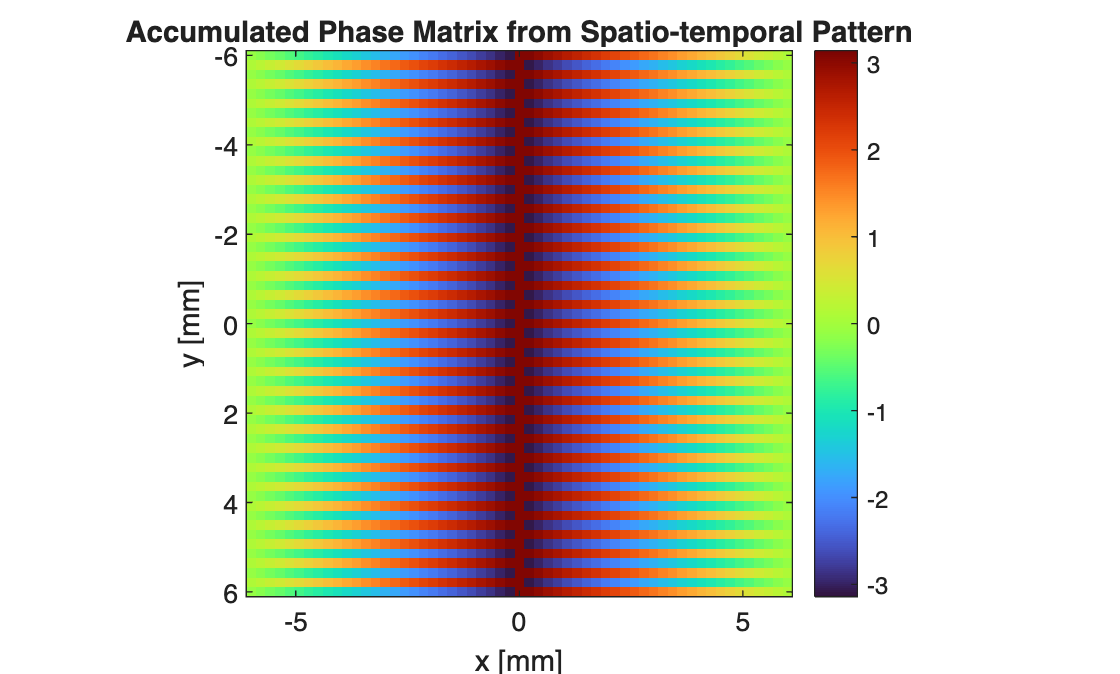

figure('Name','Accumulated Phase from Spatio-temporal Pattern');
imagesc(linspace(horizontalMin,horizontalMax,size(Acq_Phase_Matrix,1)),...
    linspace(verticalMin,verticalMax,size(Acq_Phase_Matrix,2)),Acq_Phase_Matrix);
title("Accumulated Phase Matrix from Spatio-temporal Pattern")
xlabel("x [mm]")
ylabel("y [mm]")
set(gca,'YDir','reverse'); axis image;
colormap("turbo"); 
colorbar;
clim([-pi pi])

#### Space-Time map of Recovered Frames

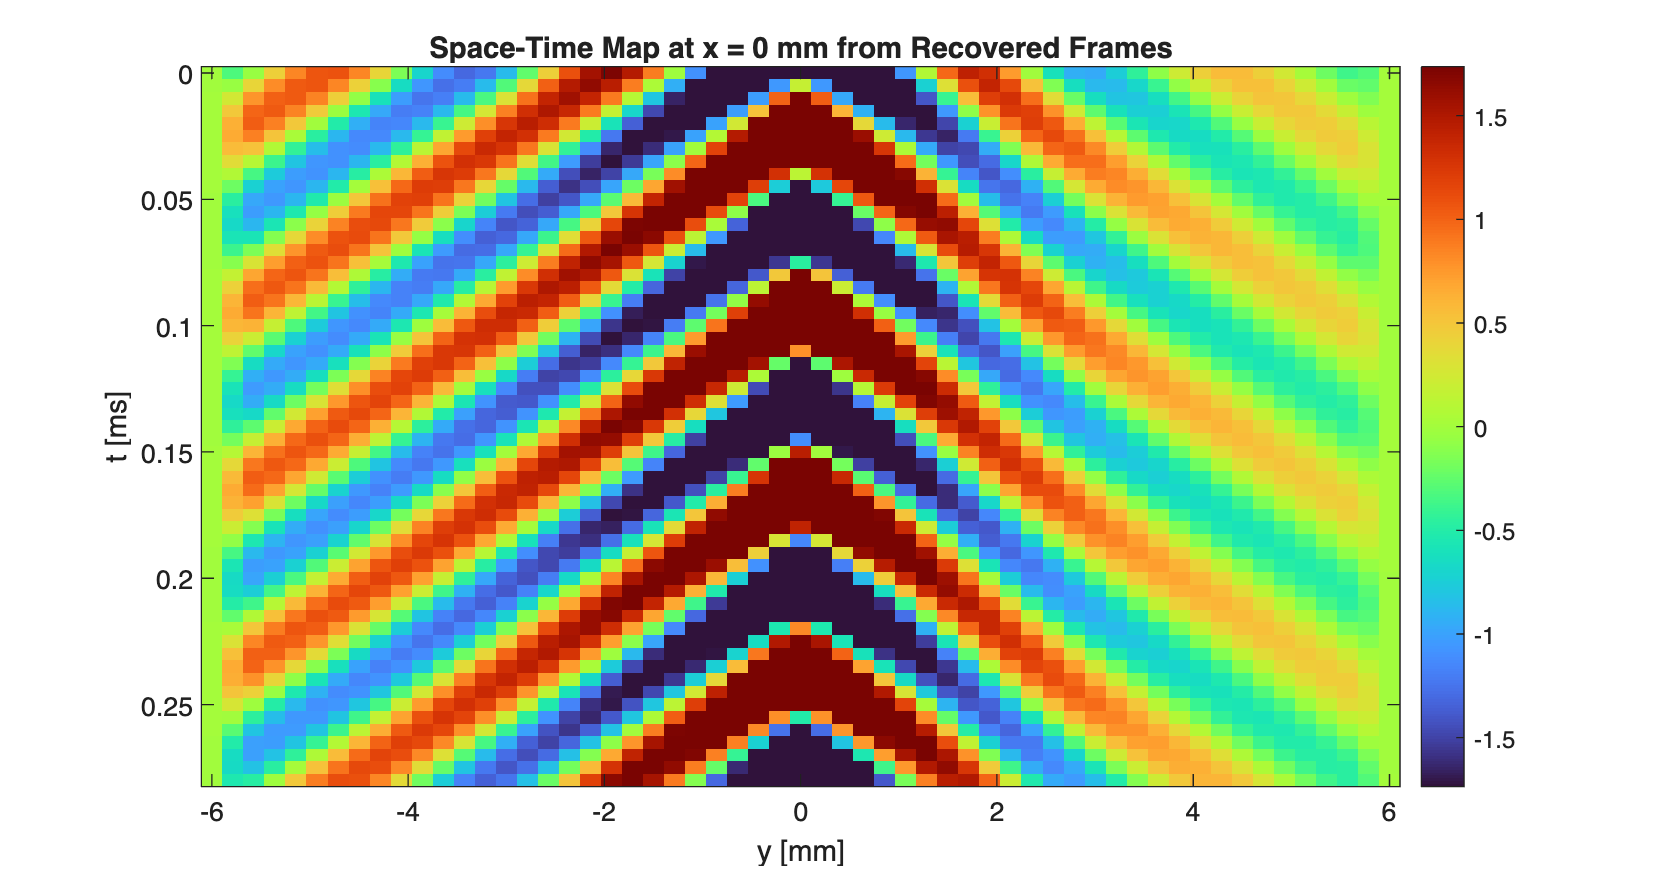

figure('Name','S-T from SBM Frames','Units','normalized','Position',[0.18 0.12 0.55 0.45]);
imagesc(x_grid*1e3,(0:Ts_OCT:(nFrames-1)*Ts_OCT)*1e3,transpose(squeeze(Recovered_Frames(:,round(size(Recovered_Frames,2)/2),:))));
title("Space-Time Map at x = 0 mm from Recovered Frames")
xlabel("y [mm]")
ylabel("t [ms]")
set(gca,'YDir','reverse'); axis tight;
colormap("turbo"); 
colorbar;
clim([-clim_robust clim_robust])

## Phase Speed Estimation on Sampled Frames using Interpolation and 2D Phase Gradient

### Preliminaries: Interpolation to symmetrical frames


Preparing SBM movie for 2D Phase Gradient...
Input SBM movie size       : [57 x 57 x 57]
Requested output grid size : [100 x 100 x 57]
SBM spatial grid is square but smaller than 100 x 100: [57 x 57].
Upsampling spatial frames to minimum fair-comparison grid: [100 x 100].
Preparation complete.
Output WavePropSim_3DMat size: [100 x 100 x 57]
Valid prepared pixels: 10000 / 10000


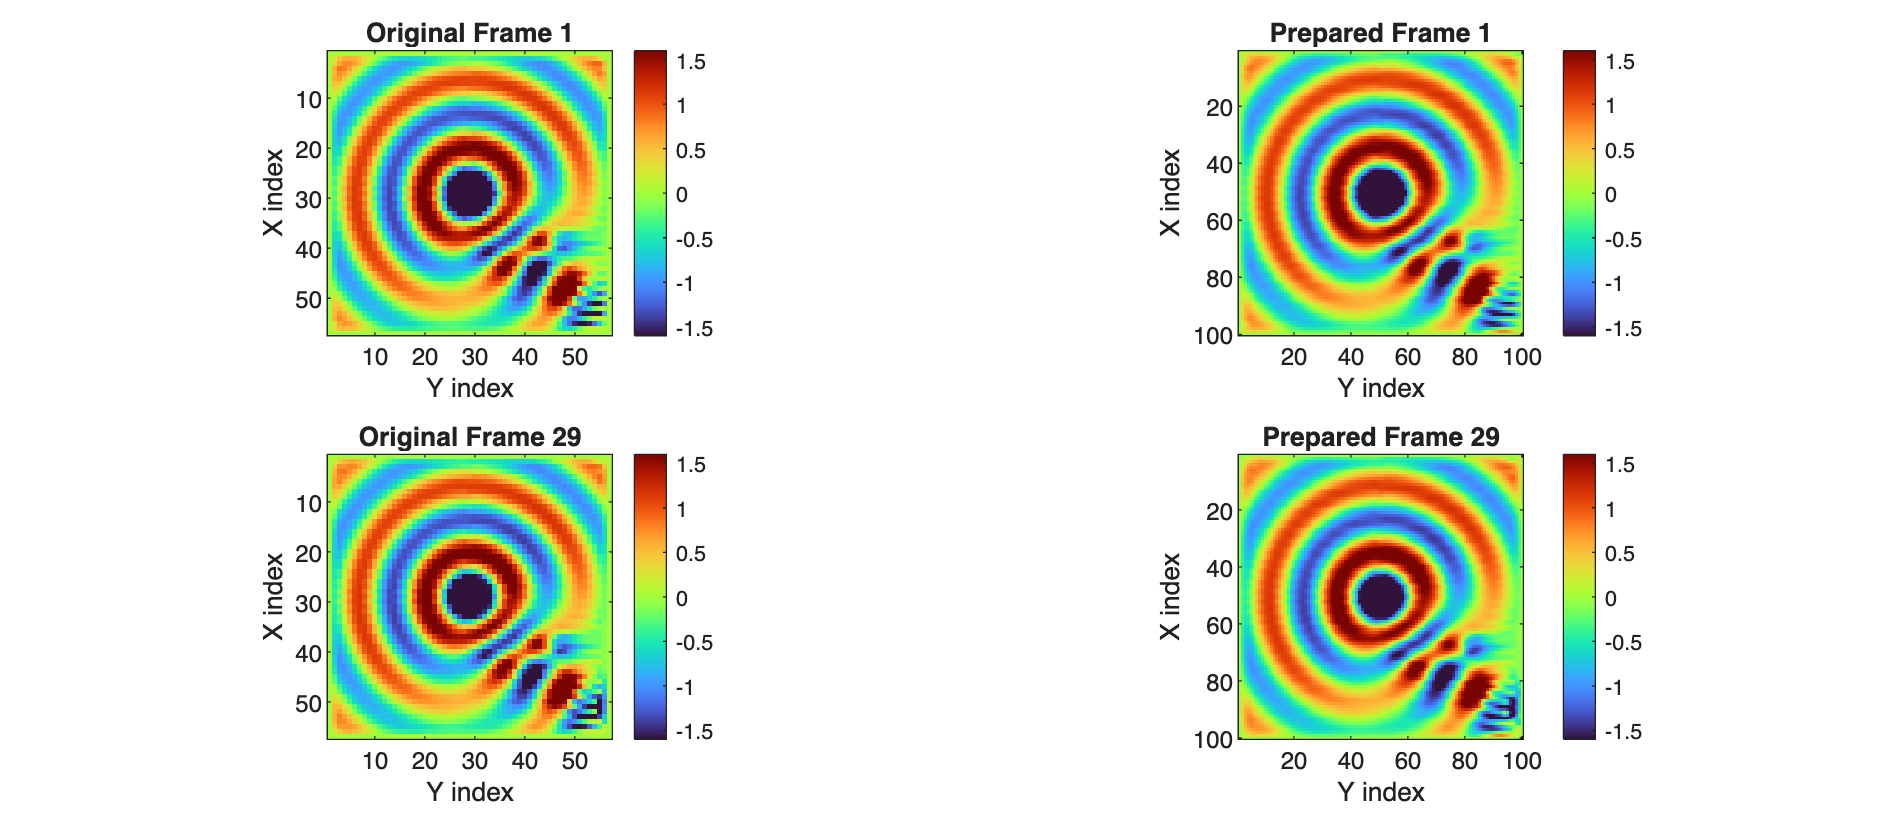

%% Prepare SBM movie for 2D Phase Gradient estimation by interpolating to max(nAscans,nBscans) x max(nAscans,nBscans):

[WavePropSim_3DMat, ValidMask_SBM, InterpOperator_SBM] = ...
    Prepare_SBM_2DPhaseGradient(Recovered_Frames, ...
                                'spline', ...      % interpolation method
                                 false, ...          % keep outside hull as NaN
                                true);              % apply light smoothing

#### Visualize prepared frames as video:

Obtain color limits for video

% Set up robust colormap: mean ± 1 sd:
mean_PreppedFrames_SBM = mean(reshape(WavePropSim_3DMat,1,[]),"omitnan");
std_PreppedFrames_SBM = std(reshape(WavePropSim_3DMat,1,[]),"omitnan");
clim_low = mean_PreppedFrames_SBM - 2*std_PreppedFrames_SBM;
clim_high = mean_PreppedFrames_SBM + 2*std_PreppedFrames_SBM;
clim_robust = min(abs(clim_low),abs(clim_high));

Obtain video:

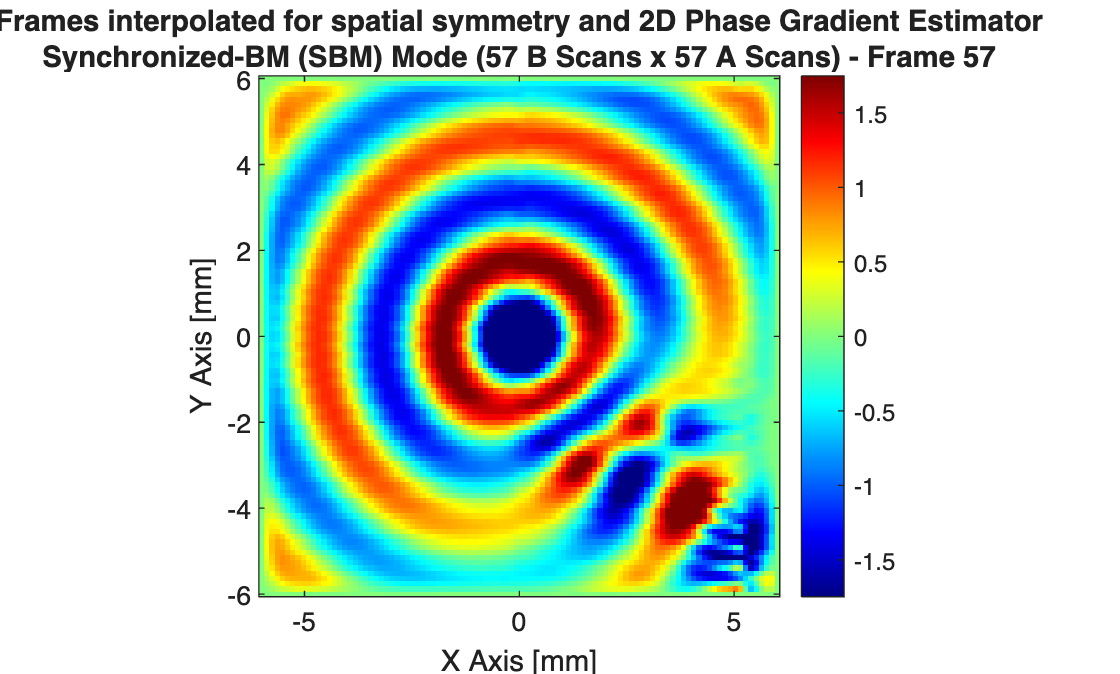

% Get video:
figure,
for i = 1:size(WavePropSim_3DMat,3)

    current_frame = flipud(WavePropSim_3DMat(:,:,i));
    imagesc(linspace(verticalMin,verticalMax,size(WavePropSim_3DMat,1)),linspace(horizontalMin,horizontalMax,size(WavePropSim_3DMat,2)),current_frame)
    axis image; set(gca,'YDir','normal');
    title({"Frames interpolated for spatial symmetry and 2D Phase Gradient Estimator",...
        sprintf("Synchronized-BM (SBM) Mode (%d B Scans x %d A Scans) - Frame %d",nBscans,nAscans,i)})
    xlabel("X Axis [mm]")
    ylabel("Y Axis [mm]")
    set(gca,'YDir','normal'); axis tight;
    clim([-clim_robust clim_robust])
    colormap("jet")
    colorbar
    %drawnow
    pause(0.1)
end

### Speed Estimation using 2D PG Approach

PhaseGradient2D_FromSims_v3()
Phase-gradient estimator: f_exc=3508.77 Hz, omega0=22046.26 rad/s, Ts_OCT=2e-05 s (fs=50000.00 Hz)
Temporal Hann windowing: 1
Nearest FFT bin: kpos=73 -> f_bin=3512.20 Hz (|f_bin-f_exc|=3.42 Hz)


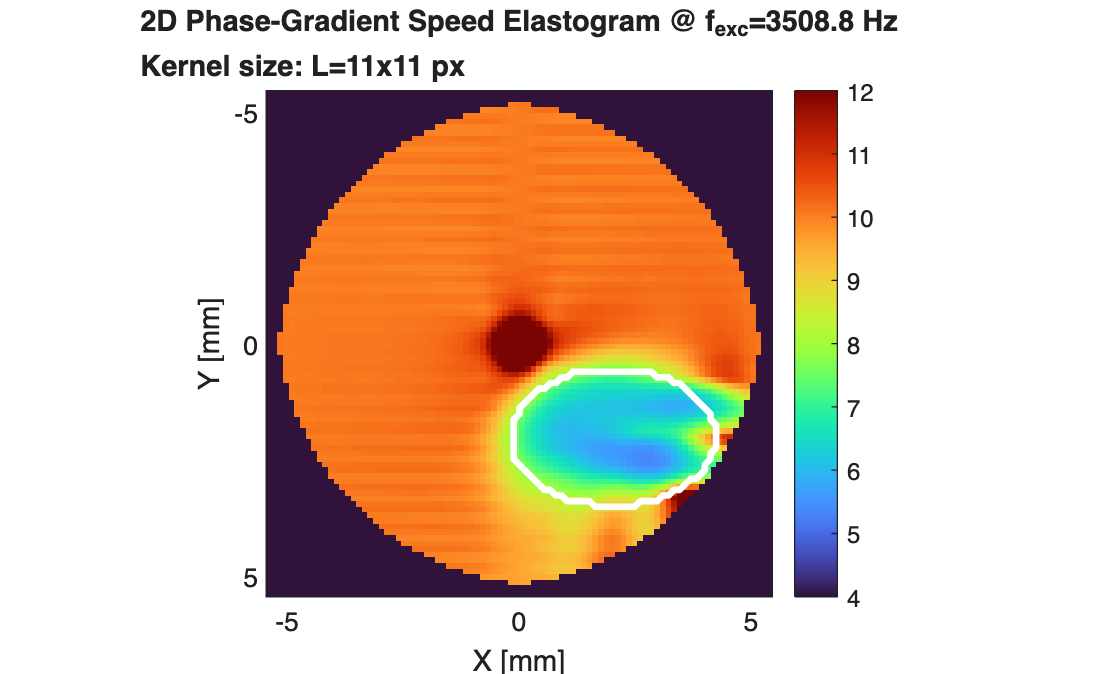

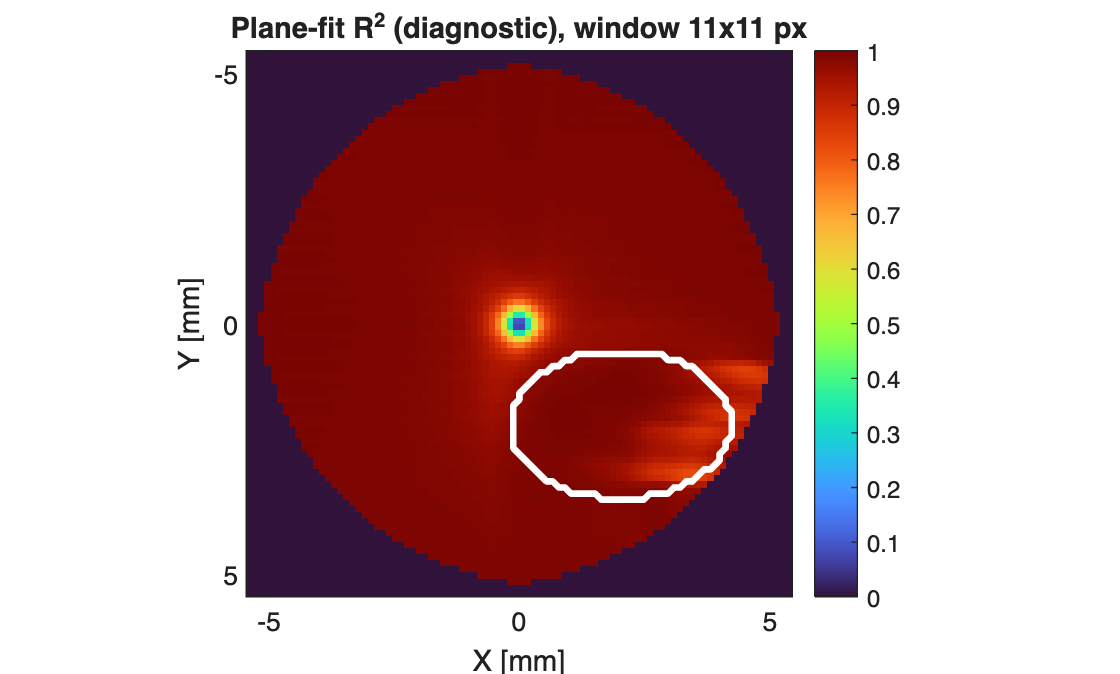

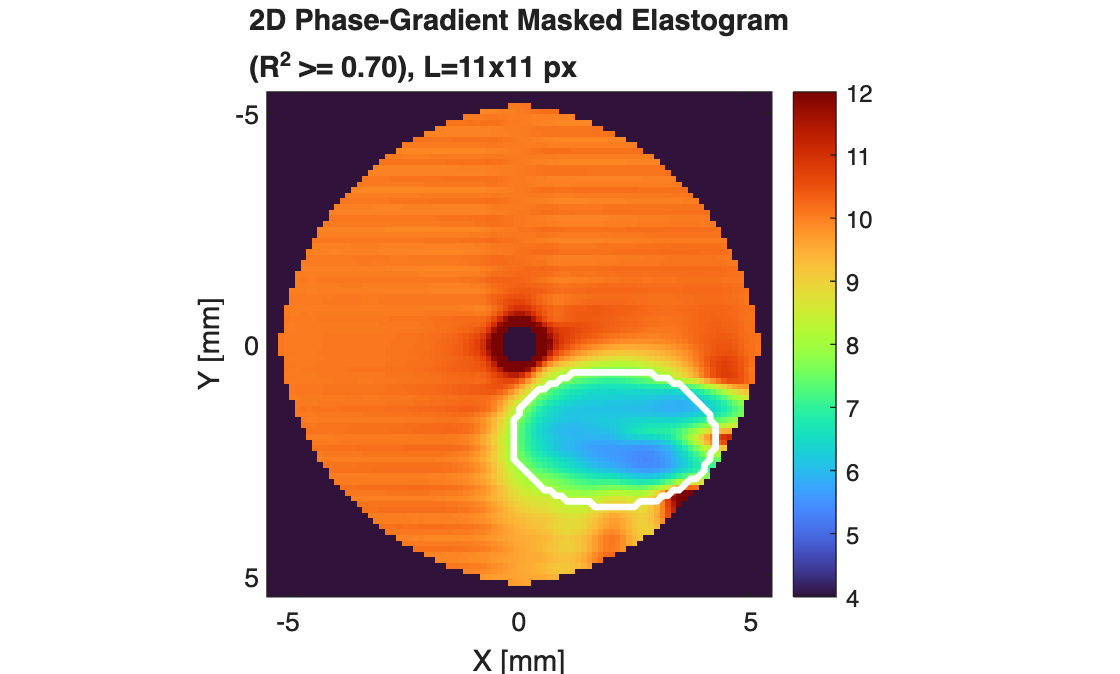

% kernel_size = 11; % L x L window for estimation
% applyTemporalWindow = true;
% % Color limits for 2D PG estimation:
clim_limits_2DPG = [4 12];

% Downsample Inclusion Mask
Inc_Mask_ReducedGrid = imresize(Inc_Mask, size(WavePropSim_3DMat, 1:2)); % Resize to match the interpolated frames
Bkg_Mask_ReducedGrid = imresize(Bkg_Mask, size(WavePropSim_3DMat, 1:2)); % Resize to match the interpolated frames

% Temporal Sample period from SBM protocol (including phase step samples):
Ts_SBM = Ts_OCT*phaseStepSamples;

[Elastogram_SBM_2DPG, R2_map_SBM_2DPG, Elastogram_Masked_SBM_2DPG, ...
 Xcrop_mm_SBM_2DPG, Ycrop_mm_SBM_2DPG, Complex_Field_Vz_SBM_2DPG, ...
 Inc_Mask_Crop_SBM_2DPG, Bkg_Mask_Crop_SBM_2DPG, Kx_SBM_2DPG, Ky_SBM_2DPG, Kmag_SBM_2DPG] = ...
    PhaseGradient2D_FromSims_v3( ...
        WavePropSim_3DMat, Inc_Mask_ReducedGrid, Bkg_Mask_ReducedGrid, ...
        kernel_size, Ts_SBM, T_excitation, ...
        horizontalMin, horizontalMax, verticalMin, verticalMax, ...
        applyTemporalWindow, clim_limits_2DPG);

### Speed Estimation using Regularized 2D PG-TV Approach

#### Explanation of Regularized Phase Gradients with Total Variation Regularization

The conventional 2D Phase Gradient (PG) estimator computes the local wave-number magnitude from the spatial phase gradients of the complex harmonic field. Although the estimator is robust under dense and noise-free sampling conditions, the resulting wave-number maps may contain local fluctuations caused by interpolation artifacts, sparse spatial sampling, motion corruption, or phase-unwrapping errors. To improve the spatial consistency of the estimated wave-number field, a Total Variation (TV) regularization step can be introduced after the phase-gradient estimation.

First, the local wave-number magnitude is computed from the estimated Cartesian phase-gradient components:


$$k(x,y)=\sqrt{k_x(x,y)^2+k_y(x,y)^2}$$


The TV regularization problem is then formulated as the minimization of a cost functional composed of a quadratic data-fidelity term and a Total Variation penalty:


$$k_{TV}=\underset{k}{\text{arg\,min}}\;\frac{1}{2}\left\|k-k_{raw}\right\|_2^2+\mu\,TV(k)$$


where $k_{raw}$ denotes the wave-number magnitude obtained from the conventional phase-gradient estimator, $\mu$ is the regularization parameter controlling the amount of smoothing, and TV(k) represents the total variation of the wave-number field.

For a two-dimensional elastogram, the isotropic Total Variation is defined as:


$$TV(k)=\sum_{i,j}\sqrt{\left(\frac{\partial k}{\partial x}\right)_{i,j}^{2}+\left(\frac{\partial k}{\partial y}\right)_{i,j}^{2}}$$


This regularization promotes piecewise-smooth wave-number maps while preserving sharp transitions associated with biomechanical boundaries. Unlike conventional low-pass filtering, the TV penalty suppresses high-frequency fluctuations without excessively blurring localized stiffness variations.

After obtaining the regularized wave-number map $k_{TV}$, the local phase speed is recovered using the standard wave relationship


$$c_{TV}(x,y)=\frac{\omega_0}{k_{TV}(x,y)}$$


where $\omega_0=2\pi f_{exc}$ is the angular excitation frequency. The resulting PG-TV elastogram therefore retains the spatial resolution of the original phase-gradient estimator while improving robustness against local estimation noise and interpolation artifacts.

#### Computation of 2D PG-TV

PhaseGradient2D_TV_FromSims()
PG-TV estimator: f_exc=3508.77 Hz, omega0=22046.26 rad/s, Ts_OCT=2e-05 s (fs=50000.00 Hz)
Temporal Hann windowing: 1
Nearest FFT bin: kpos=73 -> f_bin=3512.20 Hz (|f_bin-f_exc|=3.42 Hz)
TV mu = 250
TV iterations = 500
R2 threshold = 0.70
Valid TV pixels = 66.42 %


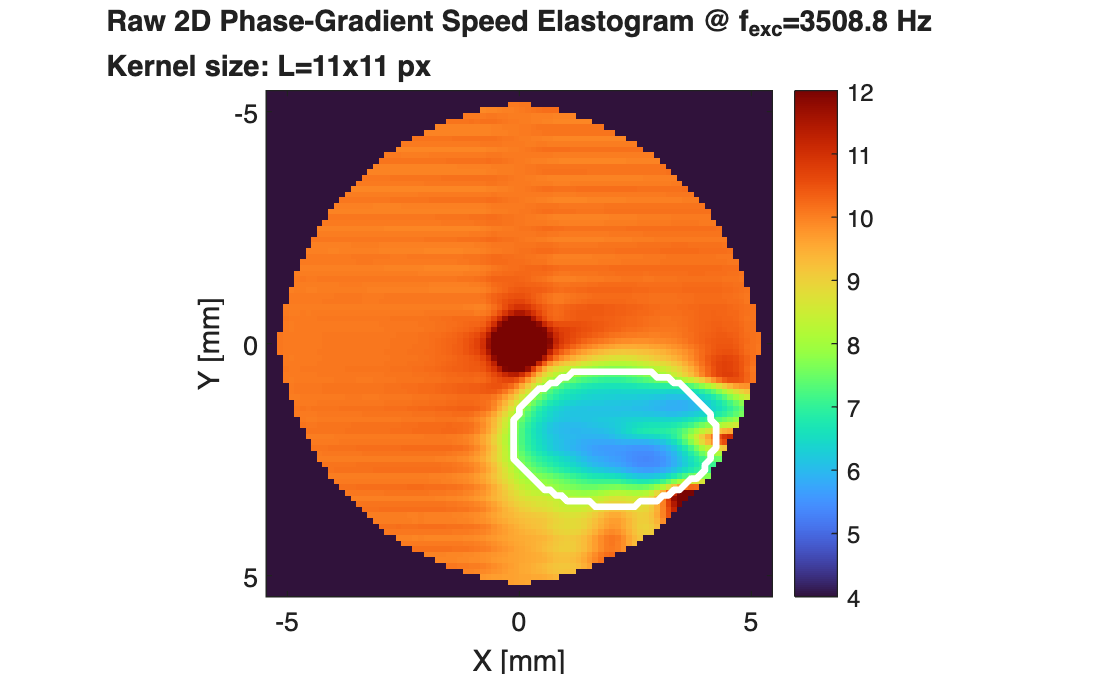

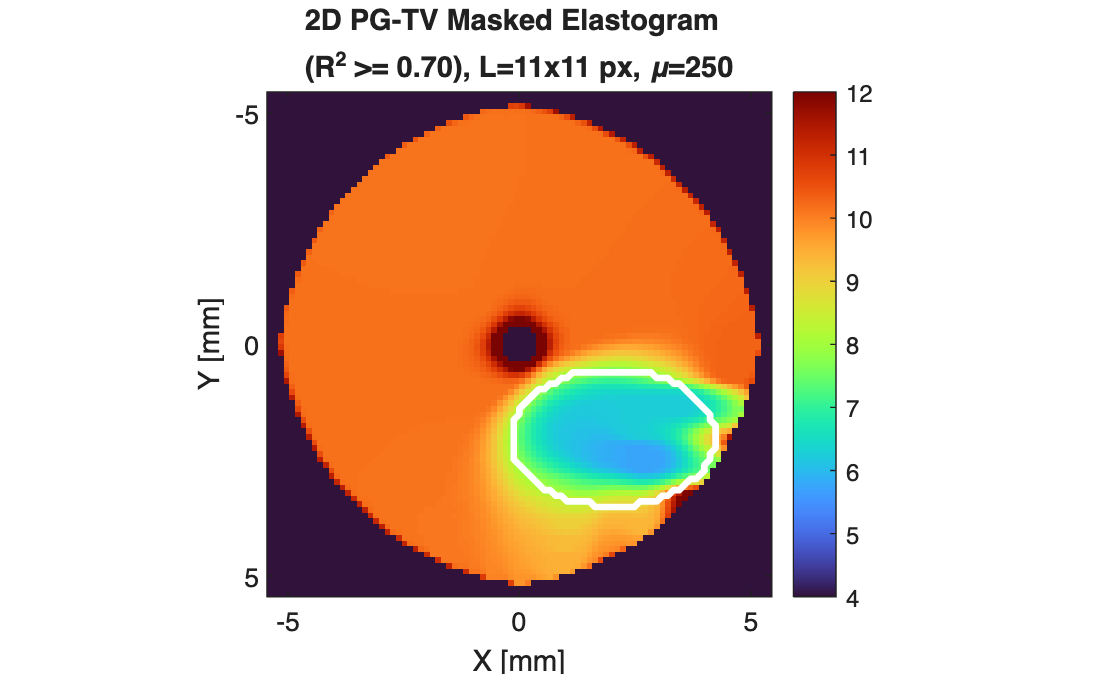

% kernel_size = 11;
% applyTemporalWindow = true;
clim_limits_PGTV = [4 12];

% Run 2D Phase Gradient on interpolated MB movie
[Elastogram_SBM_2DPG_TV, R2_map_SBM_2DPG_TV, Elastogram_Masked_SBM_2DPG_TV, ...
    Xcrop_mm_SBM_2DPG_TV, Ycrop_mm_SBM_2DPG_TV, Complex_Field_Vz_SBM_2DPG_TV, ...
    Inc_Mask_Crop_SBM_2DPG_TV, Bkg_Mask_Crop_SBM_2DPG_TV, Kx_SBM_2DPG_TV, Ky_SBM_2DPG_TV, Kmag_SBM_2DPG_TV] = ...
    PhaseGradient2D_TV_FromSims( ...
    WavePropSim_3DMat, Inc_Mask_ReducedGrid, Bkg_Mask_ReducedGrid, ...
    kernel_size, Ts_SBM, T_excitation, ...
    horizontalMin, horizontalMax, verticalMin, verticalMax, ...
    applyTemporalWindow, clim_limits_PGTV, ...
        'MuTV', 250, ...
        'TVIterations', 500, ...
        'TVTau', 0.25, ...
        'TVSigma', 0.25, ...
        'TVTheta', 1.0, ...
        'MinK', 500, ...
        'MaxK', 8000, ...
        'R2Threshold', 0.70, ...
        'DisplayFigures', true, ...
        'Verbose', true);

## Metrics Computation using Interpolation and 2D Phase Gradient

### Accuracy Error ($E_a$)

Formula for Accuracy Error ($E_a$) :

## 
$$E_a = \frac{|\hat{c} - c_{\text{GT}}|}{c_{\text{GT}}} \times 100\%$$


**Lower **$E_a$** is better**

#### Between Ground Truth and Estimation using Sampled Frames

[Ea_Bkg_2DPG, Ea_Inc_2DPG, Ea_Global_2DPG, Ea_Map_2DPG, Ea_Stats_2DPG] = Compute_AccuracyError_Masks_v2( ...
    GT_SpeedMap,  Inc_Mask, Bkg_Mask, Elastogram_Masked_SBM_2DPG);


===== Global ROI Accuracy Error Summary =====
Background:
  c_hat_mean = 10.0695 m/s | c_GT_mode = 10.0000 m/s | Ea = 0.695 % | N = 4232 pixels
Inclusion:
  c_hat_mean = 6.5201 m/s | c_GT_mode = 6.0000 m/s | Ea = 8.669 % | N = 563 pixels
Global:
  Ea_Global = 4.682 %



Show $E_a$ map:

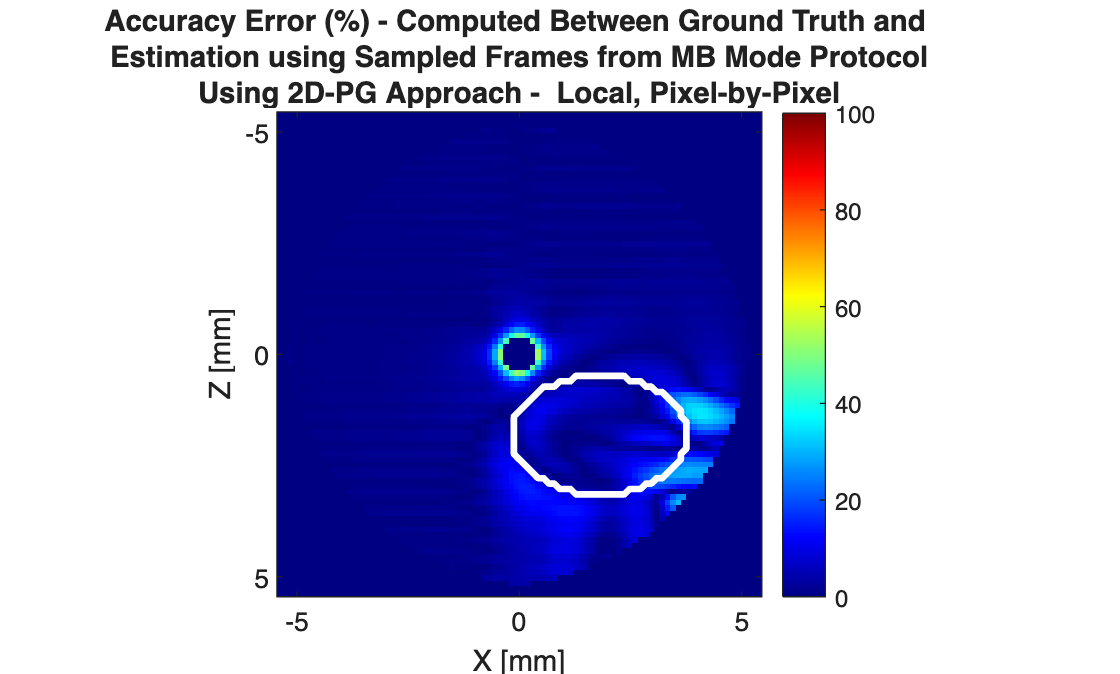

figure, colormap("jet")
imagesc(Xcrop_mm_SBM_2DPG, Ycrop_mm_SBM_2DPG,Ea_Map_2DPG), colorbar, clim([0 100])
axis image;
xlabel('X [mm]'); ylabel('Z [mm]');
title({
    'Accuracy Error (%) - Computed Between Ground Truth and ', ...
    'Estimation using Sampled Frames from MB Mode Protocol',...
    "Using 2D-PG Approach -  Local, Pixel-by-Pixel"
      });
hold on
Inc_Mask_Ea_2DPG = imresize(logical(Inc_Mask), size(Ea_Map_2DPG), 'nearest');
contour(Xcrop_mm_SBM_2DPG, Ycrop_mm_SBM_2DPG, double(Inc_Mask_Ea_2DPG), [0.5 0.5], ...
    'w', 'LineWidth', 2.5);
hold off

### Contrast to Noise Ratio (CNR)

Formula for CNR:

## 
$$\text{CNR} =  \frac{|c_{\text{background}} - c_{\text{ROI}}|}{\sqrt{\frac{\sigma_{\text{background}}^2+\sigma_{\text{ROI}}^2}{2}}}$$


**Higher CNR is better.**

[CNR_Inc_vs_Bkg_2DPG, CNR_ROI_Masks_2DPG, CNR_Stats_2DPG] = Compute_CNR_Masks( ...
    Elastogram_Masked_SBM_2DPG, Inc_Mask, Bkg_Mask);


===== CNR Summary =====
Background: mean = 10.0695 m/s | std = 0.4497 m/s | N = 4232 pixels
Inclusion : mean = 6.5201 m/s | std = 0.6545 m/s | N = 563 pixels
CNR (Inclusion vs Background) = 6.3214



### **Precision **Error ($E_p$)

Formula for Precision Error ($E_p$) :

## 
$$E_p = \frac{\sigma_{\text{ROI}}}{\mu_{\text{ROI}}} \times 100\%$$


**Lower **$E_p$** is better**

[Ep_Bkg_2DPG, Ep_Inc_2DPG, Ep_Global_2DPG, Ep_ROI_Masks_2DPG, Ep_Stats_2DPG] = Compute_PrecisionError_Masks( ...
    Elastogram_Masked_SBM_2DPG, Inc_Mask, Bkg_Mask);


===== Precision Error Summary =====
Background Ep = 4.466 % | mean = 10.0695 m/s | std = 0.4497 m/s | N = 4232 pixels
Inclusion  Ep = 10.037 % | mean = 6.5201 m/s | std = 0.6545 m/s | N = 563 pixels
Global     Ep = 12.833 % | mean = 9.6528 m/s | std = 1.2387 m/s | N = 4795 pixels



## Metrics Computation using Interpolation and 2D PG-TV

### Accuracy Error ($E_a$)

Formula for Accuracy Error ($E_a$) :

## 
$$E_a = \frac{|\hat{c} - c_{\text{GT}}|}{c_{\text{GT}}} \times 100\%$$


**Lower **$E_a$** is better**

#### Between Ground Truth and Estimation using Sampled Frames

[Ea_Bkg_2DPG_TV, Ea_Inc_2DPG_TV, Ea_Global_2DPG_TV, Ea_Map_2DPG_TV, Ea_Stats_2DPG_TV] = Compute_AccuracyError_Masks_v2( ...
    GT_SpeedMap,  Inc_Mask, Bkg_Mask, Elastogram_Masked_SBM_2DPG_TV);


===== Global ROI Accuracy Error Summary =====
Background:
  c_hat_mean = 10.1302 m/s | c_GT_mode = 10.0000 m/s | Ea = 1.302 % | N = 4232 pixels
Inclusion:
  c_hat_mean = 6.5776 m/s | c_GT_mode = 6.0000 m/s | Ea = 9.626 % | N = 563 pixels
Global:
  Ea_Global = 5.464 %



Show $E_a$ map:

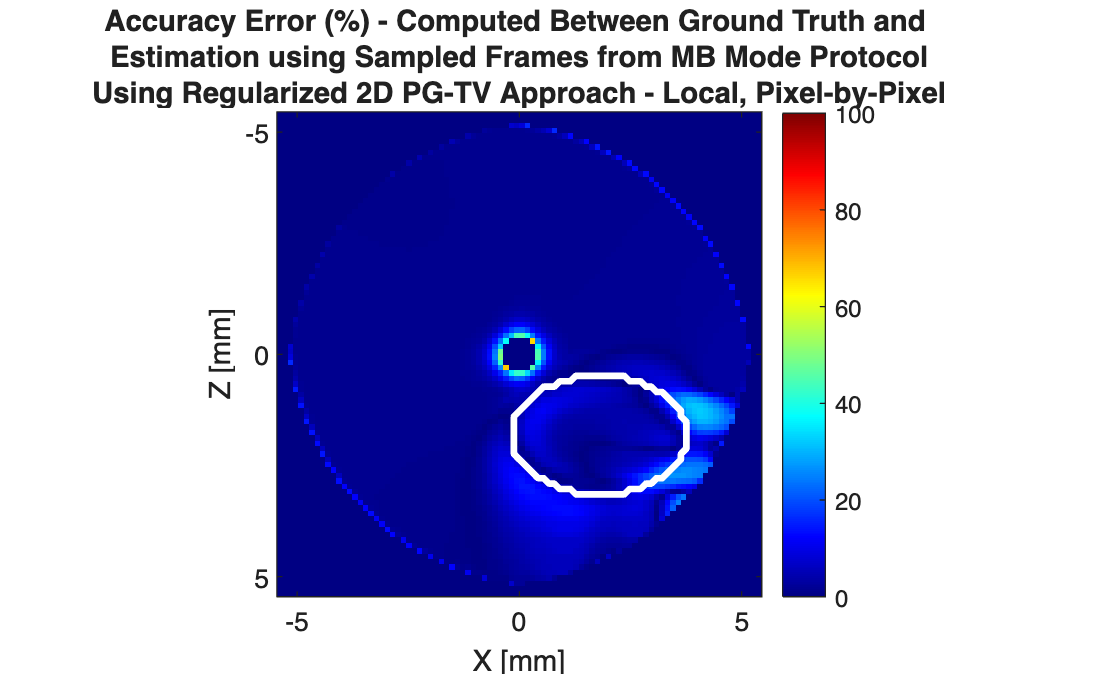

figure, colormap("jet")
imagesc(Xcrop_mm_SBM_2DPG_TV, Ycrop_mm_SBM_2DPG_TV,Ea_Map_2DPG_TV), colorbar, clim([0 100])
axis image;
xlabel('X [mm]'); ylabel('Z [mm]');
title({
    'Accuracy Error (%) - Computed Between Ground Truth and ', ...
    'Estimation using Sampled Frames from MB Mode Protocol',...
    "Using Regularized 2D PG-TV Approach - Local, Pixel-by-Pixel"
    });
hold on
Inc_Mask_Ea_2DPG_TV = imresize(logical(Inc_Mask), size(Ea_Map_2DPG_TV), 'nearest');
contour(Xcrop_mm_SBM_2DPG_TV, Ycrop_mm_SBM_2DPG_TV, double(Inc_Mask_Ea_2DPG_TV), [0.5 0.5], ...
    'w', 'LineWidth', 2.5);
hold off

### Contrast to Noise Ratio (CNR)

Formula for CNR:

## 
$$\text{CNR} =  \frac{|c_{\text{background}} - c_{\text{ROI}}|}{\sqrt{\frac{\sigma_{\text{background}}^2+\sigma_{\text{ROI}}^2}{2}}}$$


**Higher CNR is better.**

[CNR_Inc_vs_Bkg_2DPG_TV, CNR_ROI_Masks_2DPG_TV, CNR_Stats_2DPG_TV] = Compute_CNR_Masks( ...
    Elastogram_Masked_SBM_2DPG_TV, Inc_Mask, Bkg_Mask);


===== CNR Summary =====
Background: mean = 10.1302 m/s | std = 0.4278 m/s | N = 4232 pixels
Inclusion : mean = 6.5776 m/s | std = 0.6079 m/s | N = 563 pixels
CNR (Inclusion vs Background) = 6.7593



### **Precision **Error ($E_p$)

Formula for Precision Error ($E_p$) :

## 
$$E_p = \frac{\sigma_{\text{ROI}}}{\mu_{\text{ROI}}} \times 100\%$$


**Lower **$E_p$** is better**

[Ep_Bkg_2DPG_TV, Ep_Inc_2DPG_TV, Ep_Global_2DPG_TV, Ep_ROI_Masks_2DPG_TV, Ep_Stats_2DPG_TV] = Compute_PrecisionError_Masks( ...
    Elastogram_Masked_SBM_2DPG_TV, Inc_Mask, Bkg_Mask);


===== Precision Error Summary =====
Background Ep = 4.223 % | mean = 10.1302 m/s | std = 0.4278 m/s | N = 4232 pixels
Inclusion  Ep = 9.242 % | mean = 6.5776 m/s | std = 0.6079 m/s | N = 563 pixels
Global     Ep = 12.664 % | mean = 9.7131 m/s | std = 1.2300 m/s | N = 4795 pixels



## Store Metrics and Elastograms for Analysis

Now we'll store all of the metrics and results 

First, we'll define the type of experiments we've performed, as in the temporal profile of the excitation and wether or not they included saccades:

exp_type = "Harmonic_Ideal";
% Options:
% - "Harmonic_Ideal"
% - "Harmonic_Saccades"
% - "Quasi_Harmonic_Ideal"
% - "Quasi_Harmonic_Saccades"
% - "Harmonic_Ideal_Cylindrical"

Then we'll go into the appropriate directory inside our results folder:

exp_path = strcat(run_path,'/',exp_type);
try
    cd(exp_path);
catch
    % If it's not created, then we do so:
    mkdir(exp_path);
end

And now we'll store all of the relevant metrics and Elastograms for the analysis and comparison between multiple MB Multimeridian configurations:

%% ================= Store Metrics and Elastograms: SBM =====================

results_filename = sprintf( ...
    "SBM_SimResults_%d_Ascans_%d_BScans_%d_TurnSamples_%s_%s.mat", ...
    nAscans, nBscans, nTurnSamples, exp_type, prop_type_medium);

results_fullpath = fullfile(exp_path, results_filename);

Results = struct();

%% -------------------------- Metadata ----------------------------------- %
Results.Metadata = struct();
Results.Metadata.exp_type = exp_type;
Results.Metadata.protocol_type = protocol_type;
Results.Metadata.prop_type_medium = prop_type_medium;

Results.Metadata.nAscans = nAscans;
Results.Metadata.nBscans = nBscans;
Results.Metadata.nFrames = nFrames;

Results.Metadata.kernel_size = kernel_size;
Results.Metadata.applyTemporalWindow = applyTemporalWindow;
Results.Metadata.clim_limits_2DPG = clim_limits_2DPG;
Results.Metadata.clim_limits_PGTV = clim_limits_PGTV;

Results.Metadata.date_saved = string(datetime("now"));
Results.Metadata.results_filename = results_filename;
Results.Metadata.results_fullpath = results_fullpath;

%% -------------------------- Parameters --------------------------------- %
Results.Parameters = struct();

Results.Parameters.c_medium = c_medium;
Results.Parameters.Ts_OCT = Ts_OCT;
Results.Parameters.T_excitation = T_excitation;
Results.Parameters.Ts_SBM = Ts_SBM;

Results.Parameters.alpha = alpha;
Results.Parameters.N_pulses = N_pulses;
Results.Parameters.N_excitations = N_excitations;
Results.Parameters.A_Peak = A_Peak;

Results.Parameters.horizontalMin = horizontalMin;
Results.Parameters.horizontalMax = horizontalMax;
Results.Parameters.verticalMin = verticalMin;
Results.Parameters.verticalMax = verticalMax;

Results.Parameters.nPoints = nPoints;
Results.Parameters.prop_type = prop_type;
Results.Parameters.MotionCase = "ideal";
Results.Parameters.AcqFramework = protocol_type;

Results.Parameters.ExcPulseWidth = ExcPulseWidth;
Results.Parameters.AcqPulseWidth = AcqPulseWidth;
Results.Parameters.startDelay_samples = startDelay_samples;
Results.Parameters.phaseStepSamples = phaseStepSamples;
Results.Parameters.nTurnSamples = nTurnSamples;

%% -------------------------- Acquisition / sampling ---------------------- %
Results.Acquisition = struct();
Results.Acquisition.GalvoX = GalvoX;
Results.Acquisition.GalvoY = GalvoY;
Results.Acquisition.Acq_Trigger = Acq_Trigger;
Results.Acquisition.Exc_Trigger = Exc_Trigger;

if exist("Exc_aux","var")
    Results.Acquisition.Exc_aux = Exc_aux;
end

if exist("t_acqvecs","var")
    Results.Acquisition.t_acqvecs = t_acqvecs;
end

Results.SampledData = struct();

if exist("SampledFrames_vis","var")
    Results.SampledData.SampledFrames_vis = SampledFrames_vis;
end

if exist("SampledFrames_raw","var")
    Results.SampledData.SampledFrames_raw = SampledFrames_raw;
end

Results.SampledData.Acq_Phase_Matrix = Acq_Phase_Matrix;
Results.SampledData.Recovered_Frames = Recovered_Frames;

Results.SampledData.WavePropSim_3DMat_SBM_Prepared = WavePropSim_3DMat;
Results.SampledData.ValidMask_SBM = ValidMask_SBM;
Results.SampledData.InterpOperator_SBM = InterpOperator_SBM;

Results.SampledData.Inc_Mask_ReducedGrid = Inc_Mask_ReducedGrid;
Results.SampledData.Bkg_Mask_ReducedGrid = Bkg_Mask_ReducedGrid;

%% -------------------------- Ground truth / masks ------------------------ %
Results.GroundTruth = struct();
Results.GroundTruth.GT_SpeedMap = GT_SpeedMap;
Results.GroundTruth.Inc_Mask = Inc_Mask;
Results.GroundTruth.Bkg_Mask = Bkg_Mask;

Results.GroundTruth.Inc_Mask_ReducedGrid = Inc_Mask_ReducedGrid;
Results.GroundTruth.Bkg_Mask_ReducedGrid = Bkg_Mask_ReducedGrid;

%% ========================== Store estimator outputs ===================== %

%% -------------------------- 2D-PG -------------------------------------- %
Results.SBM_2DPG = struct();

Results.SBM_2DPG.Elastogram = Elastogram_SBM_2DPG;
Results.SBM_2DPG.Elastogram_Masked = Elastogram_Masked_SBM_2DPG;
Results.SBM_2DPG.R2_map = R2_map_SBM_2DPG;
Results.SBM_2DPG.Xaxis_mm = Xcrop_mm_SBM_2DPG;
Results.SBM_2DPG.Yaxis_mm = Ycrop_mm_SBM_2DPG;
Results.SBM_2DPG.Complex_Field_Vz = Complex_Field_Vz_SBM_2DPG;
Results.SBM_2DPG.Inc_Mask_Crop = Inc_Mask_Crop_SBM_2DPG;
Results.SBM_2DPG.Bkg_Mask_Crop = Bkg_Mask_Crop_SBM_2DPG;
Results.SBM_2DPG.Kx = Kx_SBM_2DPG;
Results.SBM_2DPG.Ky = Ky_SBM_2DPG;
Results.SBM_2DPG.Kmag = Kmag_SBM_2DPG;

Results.SBM_2DPG.AccuracyError = struct();
Results.SBM_2DPG.AccuracyError.Ea_Bkg = Ea_Bkg_2DPG;
Results.SBM_2DPG.AccuracyError.Ea_Inc = Ea_Inc_2DPG;
Results.SBM_2DPG.AccuracyError.Ea_Global = Ea_Global_2DPG;
Results.SBM_2DPG.AccuracyError.Ea_Map_LocalPixelwise = Ea_Map_2DPG;
Results.SBM_2DPG.AccuracyError.Ea_Stats = Ea_Stats_2DPG;

Results.SBM_2DPG.CNR = struct();
Results.SBM_2DPG.CNR.CNR_Inc_vs_Bkg = CNR_Inc_vs_Bkg_2DPG;
Results.SBM_2DPG.CNR.CNR_ROI_Masks = CNR_ROI_Masks_2DPG;
Results.SBM_2DPG.CNR.CNR_Stats = CNR_Stats_2DPG;

Results.SBM_2DPG.PrecisionError = struct();
Results.SBM_2DPG.PrecisionError.Ep_Bkg = Ep_Bkg_2DPG;
Results.SBM_2DPG.PrecisionError.Ep_Inc = Ep_Inc_2DPG;
Results.SBM_2DPG.PrecisionError.Ep_Global = Ep_Global_2DPG;
Results.SBM_2DPG.PrecisionError.Ep_ROI_Masks = Ep_ROI_Masks_2DPG;
Results.SBM_2DPG.PrecisionError.Ep_Stats = Ep_Stats_2DPG;

%% -------------------------- 2D-PG-TV ----------------------------------- %
Results.SBM_2DPG_TV = struct();

Results.SBM_2DPG_TV.Elastogram = Elastogram_SBM_2DPG_TV;
Results.SBM_2DPG_TV.Elastogram_Masked = Elastogram_Masked_SBM_2DPG_TV;
Results.SBM_2DPG_TV.R2_map = R2_map_SBM_2DPG_TV;
Results.SBM_2DPG_TV.Xaxis_mm = Xcrop_mm_SBM_2DPG_TV;
Results.SBM_2DPG_TV.Yaxis_mm = Ycrop_mm_SBM_2DPG_TV;
Results.SBM_2DPG_TV.Complex_Field_Vz = Complex_Field_Vz_SBM_2DPG_TV;
Results.SBM_2DPG_TV.Inc_Mask_Crop = Inc_Mask_Crop_SBM_2DPG_TV;
Results.SBM_2DPG_TV.Bkg_Mask_Crop = Bkg_Mask_Crop_SBM_2DPG_TV;
Results.SBM_2DPG_TV.Kx = Kx_SBM_2DPG_TV;
Results.SBM_2DPG_TV.Ky = Ky_SBM_2DPG_TV;
Results.SBM_2DPG_TV.Kmag_raw = Kmag_SBM_2DPG_TV;

if exist("Kmag_TV_SBM_2DPG_TV","var")
    Results.SBM_2DPG_TV.Kmag_TV = Kmag_TV_SBM_2DPG_TV;
elseif exist("Kmag_TV_crop","var")
    Results.SBM_2DPG_TV.Kmag_TV = Kmag_TV_crop;
end

if exist("Elastogram_raw_SBM_2DPG_TV","var")
    Results.SBM_2DPG_TV.Elastogram_raw = Elastogram_raw_SBM_2DPG_TV;
end

if exist("TVInfo_SBM_2DPG_TV","var")
    Results.SBM_2DPG_TV.TVInfo = TVInfo_SBM_2DPG_TV;
elseif exist("TVInfo","var")
    Results.SBM_2DPG_TV.TVInfo = TVInfo;
end

Results.SBM_2DPG_TV.AccuracyError = struct();
Results.SBM_2DPG_TV.AccuracyError.Ea_Bkg = Ea_Bkg_2DPG_TV;
Results.SBM_2DPG_TV.AccuracyError.Ea_Inc = Ea_Inc_2DPG_TV;
Results.SBM_2DPG_TV.AccuracyError.Ea_Global = Ea_Global_2DPG_TV;
Results.SBM_2DPG_TV.AccuracyError.Ea_Map_LocalPixelwise = Ea_Map_2DPG_TV;
Results.SBM_2DPG_TV.AccuracyError.Ea_Stats = Ea_Stats_2DPG_TV;

Results.SBM_2DPG_TV.CNR = struct();
Results.SBM_2DPG_TV.CNR.CNR_Inc_vs_Bkg = CNR_Inc_vs_Bkg_2DPG_TV;
Results.SBM_2DPG_TV.CNR.CNR_ROI_Masks = CNR_ROI_Masks_2DPG_TV;
Results.SBM_2DPG_TV.CNR.CNR_Stats = CNR_Stats_2DPG_TV;

Results.SBM_2DPG_TV.PrecisionError = struct();
Results.SBM_2DPG_TV.PrecisionError.Ep_Bkg = Ep_Bkg_2DPG_TV;
Results.SBM_2DPG_TV.PrecisionError.Ep_Inc = Ep_Inc_2DPG_TV;
Results.SBM_2DPG_TV.PrecisionError.Ep_Global = Ep_Global_2DPG_TV;
Results.SBM_2DPG_TV.PrecisionError.Ep_ROI_Masks = Ep_ROI_Masks_2DPG_TV;
Results.SBM_2DPG_TV.PrecisionError.Ep_Stats = Ep_Stats_2DPG_TV;

%% ========================== Summary table ===============================

MetricNames = [
    "Mean Wave Phase Speed [m/s] ± std - Inclusion"
    "Mean Wave Phase Speed [m/s] ± std - Background"
    "Global Accuracy Error Ea [%] - Inclusion"
    "Global Accuracy Error Ea [%] - Background"
    "Global Accuracy Error Ea [%] - Global"
    "Precision Error Ep [%] - Inclusion"
    "Precision Error Ep [%] - Background"
    "Precision Error Ep [%] - Global"
    "Contrast to Noise Ratio CNR - Inclusion vs Background"
];

Summary_2DPG = [
    format_mean_std_from_mask(Elastogram_Masked_SBM_2DPG, Inc_Mask)
    format_mean_std_from_mask(Elastogram_Masked_SBM_2DPG, Bkg_Mask)
    format_scalar(Ea_Inc_2DPG)
    format_scalar(Ea_Bkg_2DPG)
    format_scalar(Ea_Global_2DPG)
    format_scalar(Ep_Inc_2DPG)
    format_scalar(Ep_Bkg_2DPG)
    format_scalar(Ep_Global_2DPG)
    format_scalar(CNR_Inc_vs_Bkg_2DPG)
];

Summary_2DPG_TV = [
    format_mean_std_from_mask(Elastogram_Masked_SBM_2DPG_TV, Inc_Mask)
    format_mean_std_from_mask(Elastogram_Masked_SBM_2DPG_TV, Bkg_Mask)
    format_scalar(Ea_Inc_2DPG_TV)
    format_scalar(Ea_Bkg_2DPG_TV)
    format_scalar(Ea_Global_2DPG_TV)
    format_scalar(Ep_Inc_2DPG_TV)
    format_scalar(Ep_Bkg_2DPG_TV)
    format_scalar(Ep_Global_2DPG_TV)
    format_scalar(CNR_Inc_vs_Bkg_2DPG_TV)
];

Results.SummaryTable = table( ...
    MetricNames, ...
    Summary_2DPG, ...
    Summary_2DPG_TV);

Results.SummaryTable.Properties.VariableNames = { ...
    'Metric', '2D_PG', '2D_PG_TV'};

%% -------------------------- Save .mat file ------------------------------ %

save(results_fullpath, "Results", "-v7.3");

fprintf("\n===== SBM PG / PG-TV Simulation Results Saved =====\n");


===== SBM PG / PG-TV Simulation Results Saved =====


fprintf("Experiment type : %s\n", exp_type);

Experiment type : Harmonic_Ideal


fprintf("Protocol        : %s\n", protocol_type);

Protocol        : SBM


fprintf("A-scans         : %d\n", nAscans);

A-scans         : 57


fprintf("B-scans         : %d\n", nBscans);

B-scans         : 57


fprintf("Saved file      : %s\n", results_fullpath);

Saved file      : /Users/cesarestefanomachadoferrer/Desktop/Undergrad Thesis/Definitive Acquisition Sampling Simulations/Results/SBM/57_Ascans_57_BScans_57_TurnSamples/Harmonic_Ideal/SBM_SimResults_57_Ascans_57_BScans_57_TurnSamples_Harmonic_Ideal_Non_Cylindrical.mat



disp(Results.SummaryTable);

                            Metric                                   2D_PG                2D_PG_TV     
    _______________________________________________________    __________________    __________________

    "Mean Wave Phase Speed [m/s] ± std - Inclusion"            "6.5201 ± 0.6545"     "6.5776 ± 0.6079" 
    "Mean Wave Phase Speed [m/s] ± std - Background"           "10.0695 ± 0.4497"    "10.1302 ± 0.4278"
    "Global Accuracy Error Ea [%] - Inclusion"                 "8.6689"              "9.6262"          
    "Global Accuracy Error Ea [%] - Background"                "0.6950"              "1.3019"          
    "Global Accuracy Error Ea [%] - Global"                    "4.6820"              "5.4641"          
    "Precision Error Ep [%] - Inclusion"                       "10.0374"             "9.2416"          
    "Precision Error Ep [%] - Background"                      "4


%% ========================== Local helper functions ======================

function out = format_mean_std_from_mask(Elastogram, Mask)

    if ~isequal(size(Elastogram), size(Mask))
        Mask = imresize(logical(Mask), size(Elastogram), 'nearest');
    else
        Mask = logical(Mask);
    end

    vals = Elastogram(Mask);
    vals = vals(isfinite(vals));

    if isempty(vals)
        out = "NaN ± NaN";
    else
        out = sprintf("%.4f ± %.4f", mean(vals,'omitnan'), std(vals,0,'omitnan'));
        out = string(out);
    end
end

function out = format_scalar(x)

    if isempty(x) || ~isfinite(x)
        out = "NaN";
    else
        out = string(sprintf("%.4f", x));
    end
end

End timer:

toc

Elapsed time is 315.636924 seconds.
